GMOS Implementation  Demonstation

 clear
  clc


   load('AndresVals.mat')


set(0,'DefaultFigureWindowStyle','normal');

set(groot,'DefaultTextInterpreter','latex');
set(groot,'DefaultAxesTickLabelInterpreter','latex');
set(groot,'DefaultLegendInterpreter','latex');
set(groot,'DefaultAxesFontSize',26);
set(groot,'DefaultTextFontSize',28);

% -------------------------
% Constants
% -------------------------
mu_EM_JPL = 1.215058560962404e-2;
%mu_EM_JPL = andres.mu
% -------------------------
% Load one periodic orbit
% -------------------------
orbit_index= 400

orbit_index = 400

%po = pick_po_from_JPL('L1_Lyapunov_orbits_JPL_IC_Earth_Moon.csv', orbit_index);



% orbit_index= 896
% po = pick_po_from_JPL('L1_northern_halo_orbits_JPL_IC_Earth_Moon.csv', orbit_index);


%xPO0 = po.x0;          % 6x1

xPO0 = andres.X0

xPO0 =     0.9767
   -0.0334
    0.1000
   -0.0737
   -0.0627
    0.4674


%TPO  = po.T;           % scalar

TPO= 1.7*andres.T

TPO = 2.4811


% 
% x0_Kaushik=[0.8533092408794802, -0.10002264189296393,  0, -0.06943835422503508,  0.008020539706976249,  0.0]
% TP0_Kaushik= 2.8635612043970644
% xPO0 = po.x0;          % 6x1
% TPO  = po.T;           % scalar
% 
% 
% 
% 
% xPO0 = x0_Kaushik;          % 6x1
% TPO  = TP0_Kaushik;  
JC_Lyap=Jacobi_Constant(xPO0, mu_EM_JPL)

JC_Lyap = 2.9432


fprintf('Using orbit index  %.15f\n', orbit_index');

Using orbit index  400.000000000000000


fprintf('TPO = %.15f\n', TPO);

TPO = 2.481107075332055


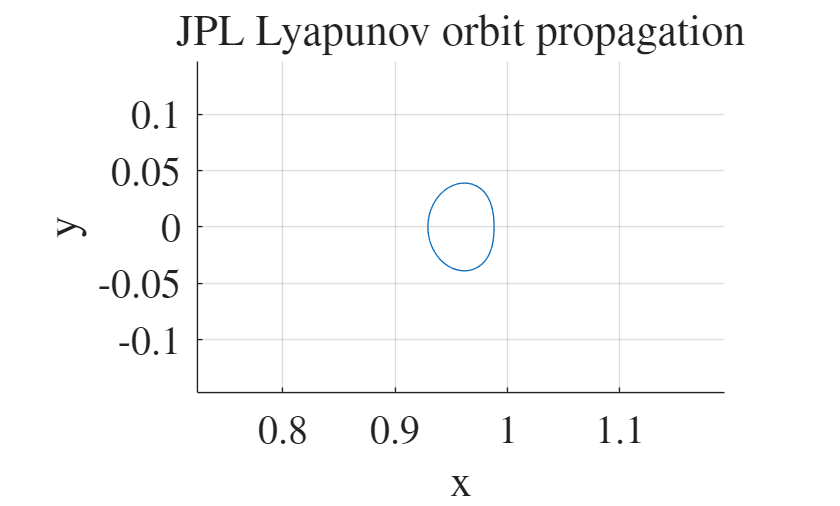


% -------------------------
% Quick trajectory plot (optional)
% -------------------------
[t_eval, Y_eval] = IntegrateCR3BP_ODE89(xPO0, [0, TPO], mu_EM_JPL, 1e3);

figure;
hold on; grid on; axis equal;
plot3(Y_eval(:,1), Y_eval(:,2), Y_eval(:,3));
xlabel('x'); ylabel('y'); zlabel('z');
title('JPL Lyapunov orbit propagation');


% -------------------------
% Closure test (must be small)
% -------------------------
ode_opts = odeset('RelTol', 1e-12, 'AbsTol', 1e-12);

sol = ode89(@(t,Y) CR3BP_mu(t, Y, mu_EM_JPL), [0, TPO], xPO0, ode_opts);
x_end = sol.y(:, end);

fprintf('PO closure error ||Phi^T(xPO0)-xPO0|| = %.3e\n', norm(x_end - xPO0));

PO closure error ||Phi^T(xPO0)-xPO0|| = 2.539e-01


Ctarget = JC_Lyap

Ctarget = 2.9432



% Choose N smaller for the first Newton test
N = 51;

% Build init using your existing GMOS initialization pipeline
demo = gmos_demo_invariance_only(mu_EM_JPL, xPO0, TPO, N, 1e-6, false, 'vertical');

Mode: vertical
Eigenvector projections: planar 2.130e-01, vertical 9.771e-01
Init amplitude [x y z xd yd zd] = [9.56e-08 2.81e-07 6.34e-07 2.07e-07 2.24e-07 1.85e-06]
Max init amplitude: component 6, amp = 1.846e-06
Linearization test at j=1:
  ||dx0||      = 9.896e-07
  ||dx1||      = 2.539e-01
  ||dx1_lin||  = 8.114e-07
  ||dx1-dx1lin|| = 2.539e-01
Inf residual: +rho 2.070e-01, -rho 2.070e-01, using sign 1
||Finv||2   = 1.813e+00
||Finv||inf = 2.070e-01


init = demo.init;

% Reference for phase conditions in the first solve
Xref   = init.X0;
Tref   = init.T0;
rhoref = init.rho0;

% Initial unknown vector z = [X0(:); T; rho]
z0 = gmos_pack_z(init.X0, init.T0, init.rho0);

optsN = struct();
optsN.maxIter = 12;
optsN.tolInf  = 1e-10;
optsN.verbose = true;

[z_sol, info] = gmos_newton_fixC_analytic( ...
    z0, N, mu_EM_JPL, Xref, Tref, rhoref, Ctarget, ode_opts, optsN);

Newton iter  1: ||F||inf = 2.070e-01, ||F||2 = 1.813e+00
Newton iter  2: ||F||inf = 3.399e+07, ||F||2 = 3.399e+07
Newton iter  3: ||F||inf = 9.122e+06, ||F||2 = 9.122e+06
Newton iter  4: ||F||inf = 1.581e+06, ||F||2 = 1.581e+06
Newton iter  5: ||F||inf = 4.138e+04, ||F||2 = 4.140e+04
Newton iter  6: ||F||inf = 9.185e+03, ||F||2 = 9.189e+03
Newton iter  7: ||F||inf = 2.250e+03, ||F||2 = 2.251e+03
Newton iter  8: ||F||inf = 5.607e+02, ||F||2 = 5.609e+02
Newton iter  9: ||F||inf = 1.408e+02, ||F||2 = 1.409e+02
Newton iter 10: ||F||inf = 3.590e+01, ||F||2 = 3.592e+01
Newton iter 11: ||F||inf = 9.068e+00, ||F||2 = 9.071e+00
Newton iter 12: ||F||inf = 1.416e+00, ||F||2 = 1.416e+00


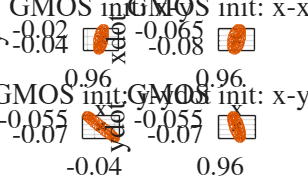

Mode: vertical
Eigenvector projections: planar 2.130e-01, vertical 9.771e-01
Init amplitude [x y z xd yd zd] = [9.56e-03 2.81e-02 6.34e-02 2.07e-02 2.24e-02 1.85e-01]
Max init amplitude: component 6, amp = 1.846e-01
Linearization test at j=1:
  ||dx0||      = 9.896e-02
  ||dx1||      = 3.636e-01
  ||dx1_lin||  = 8.114e-02
  ||dx1-dx1lin|| = 2.864e-01
Inf residual: +rho 3.028e-01, -rho 3.609e-01, using sign 1
||Finv||2   = 2.075e+00
||Finv||inf = 3.028e-01


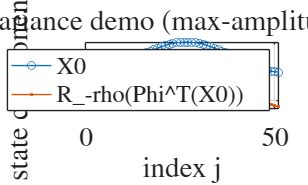

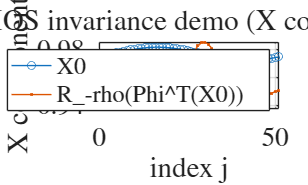

% -------------------------
% GMOS invariance-only demo
% -------------------------
N = 51;
K = 1e-1;
doPlot = true;

demo = gmos_demo_invariance_only(mu_EM_JPL, xPO0, TPO, N, K, doPlot, 'vertical');


init = demo.init;    % make sure init is defined now

% -------------------------
% Shift self-test (must use the curve, not a single state)
% -------------------------
X0 = init.X0;  % 6xN

X0p = gmos_shift_curve_fft(X0,  init.rho0);
X0m = gmos_shift_curve_fft(X0, -init.rho0);

fprintf('Shift self-test:\n');

Shift self-test:


fprintf('  ||X0p-X0||inf = %.3e\n', norm(X0p(:) - X0(:), inf));

  ||X0p-X0||inf = 5.824e-02


fprintf('  ||X0m-X0||inf = %.3e\n', norm(X0m(:) - X0(:), inf));

  ||X0m-X0||inf = 5.824e-02


fprintf('  ||X0p-X0m||inf = %.3e\n', norm(X0p(:) - X0m(:), inf));

  ||X0p-X0m||inf = 1.105e-01



% -------------------------
% Perturbed vs unperturbed closeness test
% -------------------------
sol0 = ode89(@(t,Y) CR3BP_mu(t, Y, mu_EM_JPL), [0, TPO], xPO0, ode_opts);
x_end0 = sol0.y(:, end);

x0j = init.X0(:, 1);
solp = ode89(@(t,Y) CR3BP_mu(t, Y, mu_EM_JPL), [0, TPO], x0j, ode_opts);
x_endp = solp.y(:, end);

fprintf('Closeness test:\n');

Closeness test:


fprintf('  ||x0j - xPO0||       = %.3e\n', norm(x0j - xPO0));

  ||x0j - xPO0||       = 9.896e-02


fprintf('  ||x_endp - x_end0||  = %.3e\n', norm(x_endp - x_end0));

  ||x_endp - x_end0||  = 1.155e-01


fprintf('  ||x_end0 - xPO0||    = %.3e (closure)\n', norm(x_end0 - xPO0));

  ||x_end0 - xPO0||    = 2.539e-01 (closure)


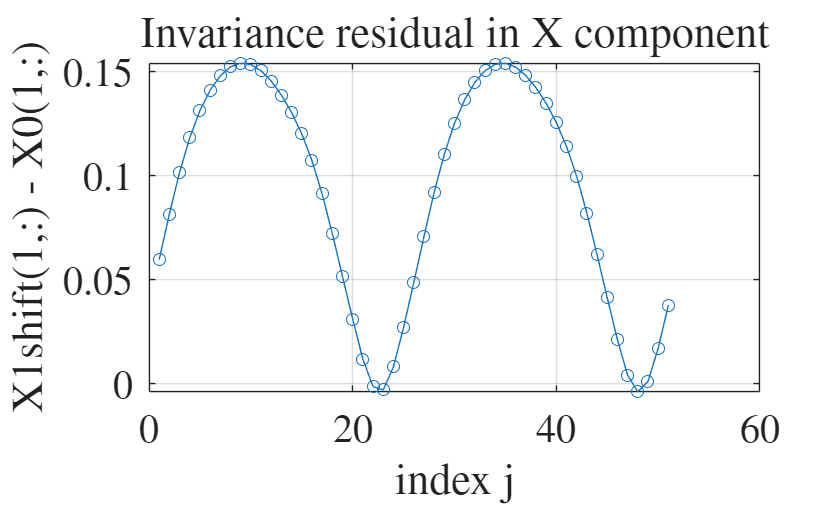

figure;
plot(1:N, (demo.X1shift(1,:) - demo.init.X0(1,:)), 'o-');
grid on;
xlabel('index j');
ylabel('X1shift(1,:) - X0(1,:)');
title('Invariance residual in X component');

tic

% Choose N smaller for the first Newton test
N = 51;

% Build init (use your existing pipeline)
demo = gmos_demo_invariance_only(mu_EM_JPL, xPO0, TPO, N, 1e-6, false, 'vertical');

Mode: vertical
Eigenvector projections: planar 8.128e-14, vertical 1.000e+00
Init amplitude [x y z xd yd zd] = [0.00e+00 1.42e-19 2.40e-07 7.61e-20 0.00e+00 1.98e-06]
Max init amplitude: component 6, amp = 1.984e-06
Linearization test at j=1:
  ||dx0||      = 9.928e-07
  ||dx1||      = 5.345e-07
  ||dx1_lin||  = 5.345e-07
  ||dx1-dx1lin|| = 9.313e-11
Inf residual: +rho 7.473e-11, -rho 1.686e-06, using sign 1
||Finv||2   = 3.874e-10
||Finv||inf = 7.473e-11


init = demo.init;

% Reference for phase conditions (first solve)
Xref   = init.X0;
Tref   = init.T0;
rhoref = init.rho0;

% Initial unknown vector
z0 = gmos_pack_z(init.X0, init.T0, init.rho0);

% Fix T exactly to the periodic orbit period
Ttarget = TPO;

optsN = struct();
optsN.maxIter = 12;
optsN.tolInf  = 1e-10;
optsN.verbose = true;

[z_sol, info] = gmos_newton_fixT_analytic(z0, N, mu_EM_JPL, Xref, Tref, rhoref, Ttarget, ode_opts, optsN);

Newton iter  1: ||F||inf = 7.307e-11, ||F||2 = 3.778e-10



[X0_sol, T_sol, rho_sol] = gmos_unpack_z(z_sol, N);
fprintf('Solved: T = %.15f, rho = %.15f\n', T_sol, rho_sol);

Solved: T = 4.593485557331357, rho = 1.013999616412891



toc

Elapsed time is 0.827885 seconds.


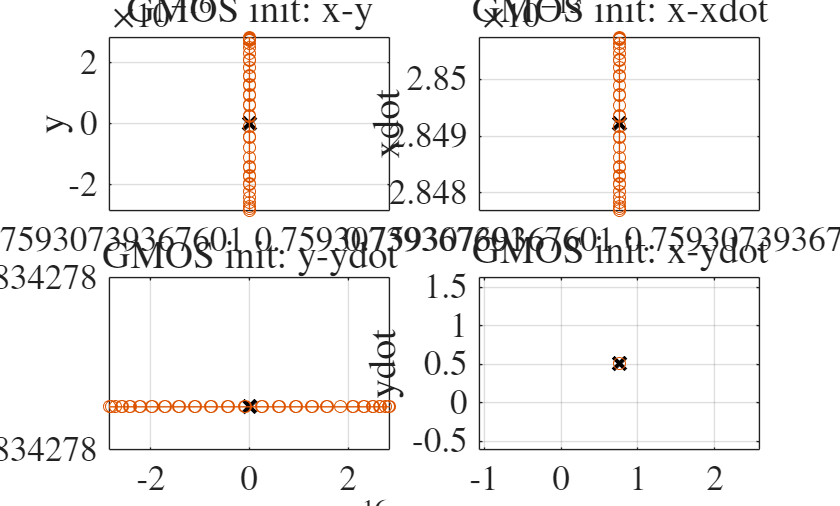

Mode: vertical
Eigenvector projections: planar 8.128e-14, vertical 1.000e+00
Init amplitude [x y z xd yd zd] = [0.00e+00 5.68e-16 9.60e-04 3.04e-16 0.00e+00 7.93e-03]
Max init amplitude: component 6, amp = 7.935e-03
Linearization test at j=1:
  ||dx0||      = 3.971e-03
  ||dx1||      = 2.877e-03
  ||dx1_lin||  = 2.138e-03
  ||dx1-dx1lin|| = 1.929e-03
Inf residual: +rho 1.561e-03, -rho 6.742e-03, using sign 1
||Finv||2   = 8.446e-03
||Finv||inf = 1.561e-03


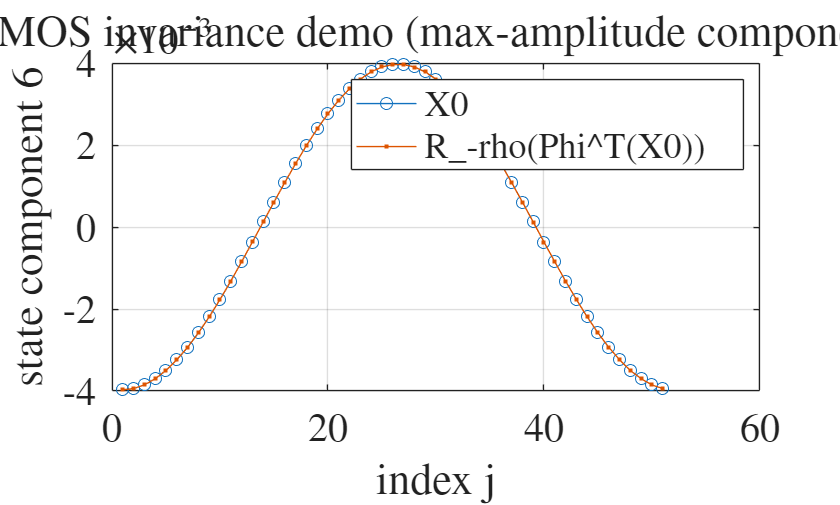

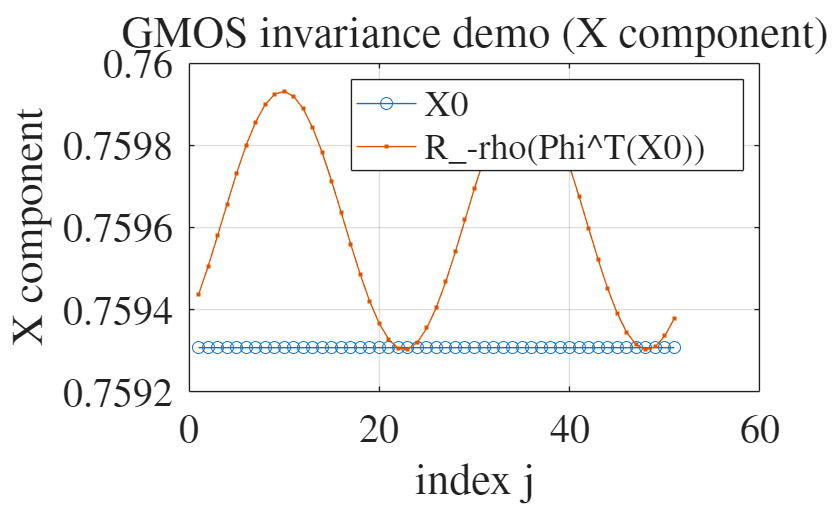

% Settings

ode_opts = odeset('RelTol',1e-12,'AbsTol',1e-12);
Ttarget = TPO;

% Build two inits with different K
demo0 = gmos_demo_invariance_only(mu_EM_JPL, xPO0, TPO, N, 4e-3, true, 'vertical');

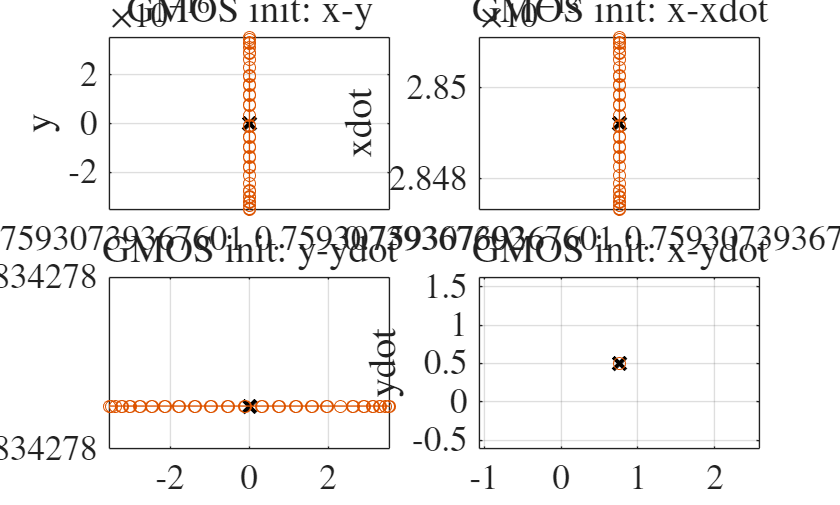

Mode: vertical
Eigenvector projections: planar 8.128e-14, vertical 1.000e+00
Init amplitude [x y z xd yd zd] = [0.00e+00 7.10e-16 1.20e-03 3.80e-16 0.00e+00 9.92e-03]
Max init amplitude: component 6, amp = 9.918e-03
Linearization test at j=1:
  ||dx0||      = 4.964e-03
  ||dx1||      = 4.022e-03
  ||dx1_lin||  = 2.672e-03
  ||dx1-dx1lin|| = 3.011e-03
Inf residual: +rho 2.440e-03, -rho 8.428e-03, using sign 1
||Finv||2   = 1.319e-02
||Finv||inf = 2.440e-03


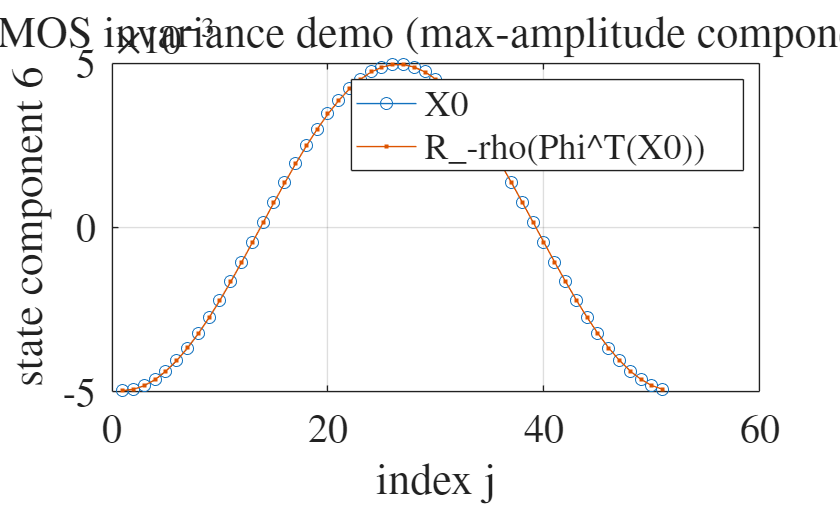

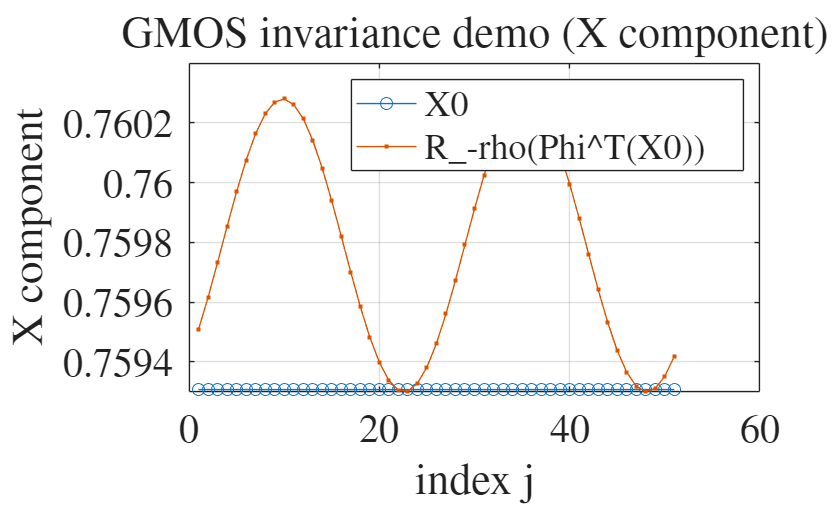

demo1 = gmos_demo_invariance_only(mu_EM_JPL, xPO0, TPO, N, 5e-3, true, 'vertical');


init0 = demo0.init;
init1 = demo1.init;

% Reference for phase conditions (paper): use the first solution as reference
Xref   = init0.X0;
Tref   = init0.T0;
rhoref = init0.rho0;

% Solve both with fixed T analytic Newton (no pseudo arclength yet)
z0 = gmos_pack_z(init0.X0, init0.T0, init0.rho0);
z1 = gmos_pack_z(init1.X0, init1.T0, init1.rho0);

optsN = struct('maxIter', 12, 'tolInf', 1e-10, 'verbose', true);

[z0_sol, ~] = gmos_newton_fixT_analytic(z0, N, mu_EM_JPL, Xref, Tref, rhoref, Ttarget, ode_opts, optsN);

Newton iter  1: ||F||inf = 1.561e-03, ||F||2 = 8.446e-03
Newton iter  2: ||F||inf = 1.648e-05, ||F||2 = 8.410e-05
Newton iter  3: ||F||inf = 3.726e-05, ||F||2 = 2.020e-04
Newton iter  4: ||F||inf = 4.924e-09, ||F||2 = 1.959e-08
Newton iter  5: ||F||inf = 2.088e-13, ||F||2 = 7.914e-13


[z1_sol, ~] = gmos_newton_fixT_analytic(z1, N, mu_EM_JPL, Xref, Tref, rhoref, Ttarget, ode_opts, optsN);

Newton iter  1: ||F||inf = 2.440e-03, ||F||2 = 1.319e-02
Newton iter  2: ||F||inf = 2.556e-04, ||F||2 = 1.353e-03
Newton iter  3: ||F||inf = 8.552e-04, ||F||2 = 4.628e-03
Newton iter  4: ||F||inf = 2.340e-06, ||F||2 = 1.082e-05
Newton iter  5: ||F||inf = 1.414e-08, ||F||2 = 5.730e-08
Newton iter  6: ||F||inf = 5.625e-13, ||F||2 = 2.335e-12



% Continue the family
ds = 0.9e-2;      % step in z-space (tune)

%ds = 1e-4;      % step in z-space (tune)
nSteps =1

nSteps = 1


resultsFile = 'fam_fixT_LyapL1.mat';


    tic
    fam = gmos_continue_fixT_family( ...
        z0_sol, z1_sol, nSteps, ds, N, mu_EM_JPL, Ttarget, ode_opts, optsN);

Newton iter  1: ||F||inf = 6.673e-04, ||F||2 = 3.614e-03
Newton iter  2: ||F||inf = 1.649e-06, ||F||2 = 6.250e-06
Newton iter  3: ||F||inf = 4.904e-09, ||F||2 = 2.299e-08
Newton iter  4: ||F||inf = 2.246e-13, ||F||2 = 7.811e-13
Continuation step 1/1: T = 4.593485557331357, rho = 1.013813219672334, final ||F||inf = 2.246e-13


   toc

Elapsed time is 2.239281 seconds.


    %save(resultsFile, ...
      %  'fam', 'z0_sol', 'z1_sol', 'nSteps', 'ds', 'N', 'mu_EM_JPL', ...
     %   'Ttarget', 'ode_opts', 'optsN', '-v7.3');

    fprintf('Saved family and settings to %s\n', resultsFile);

Saved family and settings to fam_fixT_LyapL1.mat


   load(resultsFile, ...
       'fam', 'z0_sol', 'z1_sol', 'nSteps', 'ds', 'N', 'mu_EM_JPL', ...
       'Ttarget', 'ode_opts', 'optsN');

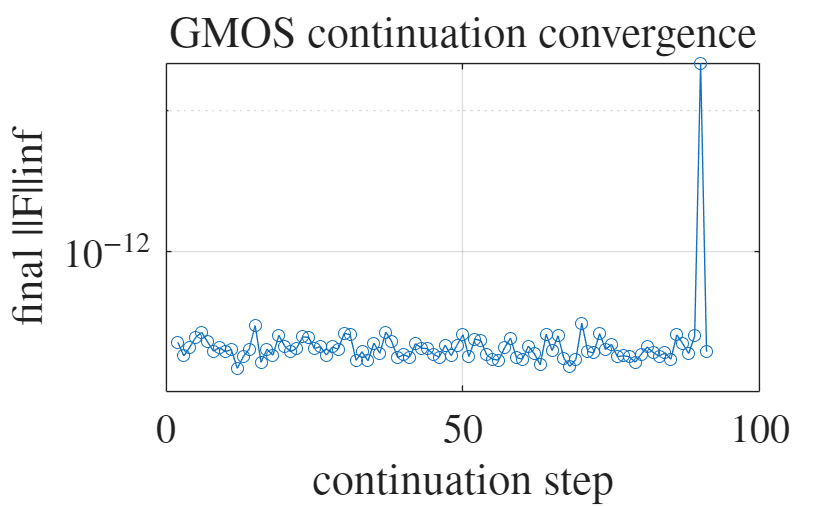

k = 0:(numel(fam.rho)-1);   % step index (adjust if you start at 1/2 seeds)

figure;
semilogy(k, fam.normInf, 'o-');
grid on;
xlabel('continuation step');
ylabel('final ||F||inf');
title('GMOS continuation convergence');

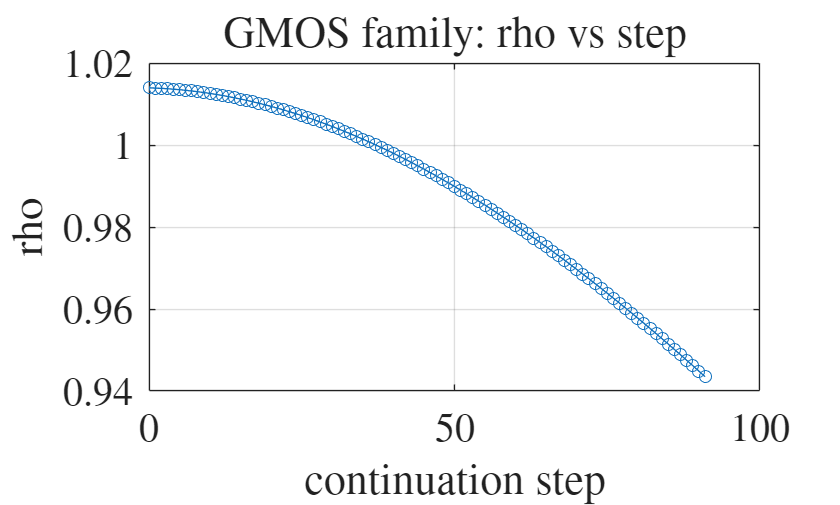



k = 0:(numel(fam.rho)-1);

figure;
plot(k, fam.rho, 'o-');
grid on;
xlabel('continuation step');
ylabel('rho');
title('GMOS family: rho vs step');

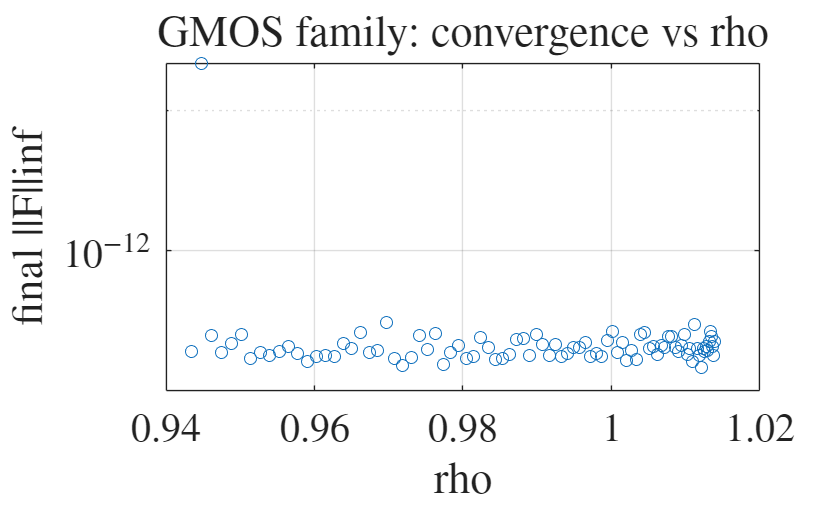




figure;
semilogy(fam.rho, fam.normInf, 'o');
grid on;
xlabel('rho');
ylabel('final ||F||inf');
title('GMOS family: convergence vs rho');

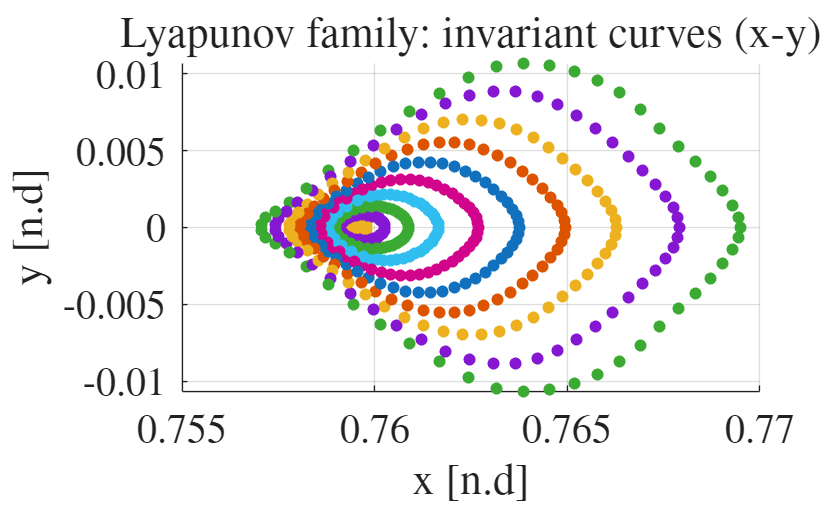

  % must match your continuation N

idxList = unique(round(linspace(1, numel(fam.z), min(12, numel(fam.z)))));

figure; hold on; grid on; 

for ii = idxList(:).'
    z = fam.z{ii};
    [X0, T, rho] = gmos_unpack_z(z, N);

    scatter3(X0(1,:), X0(2,:),X0(3,:), 'filled');   % x-y projection of the curve
end
xlabel('x [n.d]'); ylabel('y [n.d]');
title('Lyapunov family: invariant curves (x-y)');

%legend(arrayfun(@(ii) sprintf('step %d', ii-1), idxList, 'UniformOutput', false));

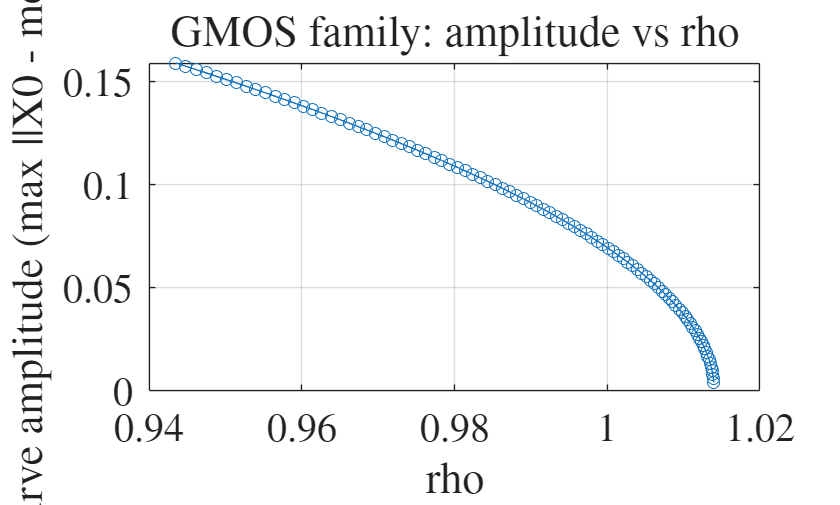


nSol = numel(fam.z);

amp = zeros(nSol,1);
for i = 1:nSol
    [X0, ~, ~] = gmos_unpack_z(fam.z{i}, N);
    Xm = mean(X0, 2);
    amp(i) = max(vecnorm(X0 - Xm, 2, 1));  % max column 2-norm deviation
end

figure;
plot(fam.rho, amp, 'o-');
grid on;
xlabel('rho');
ylabel('curve amplitude (max ||X0 - mean||)');
title('GMOS family: amplitude vs rho');

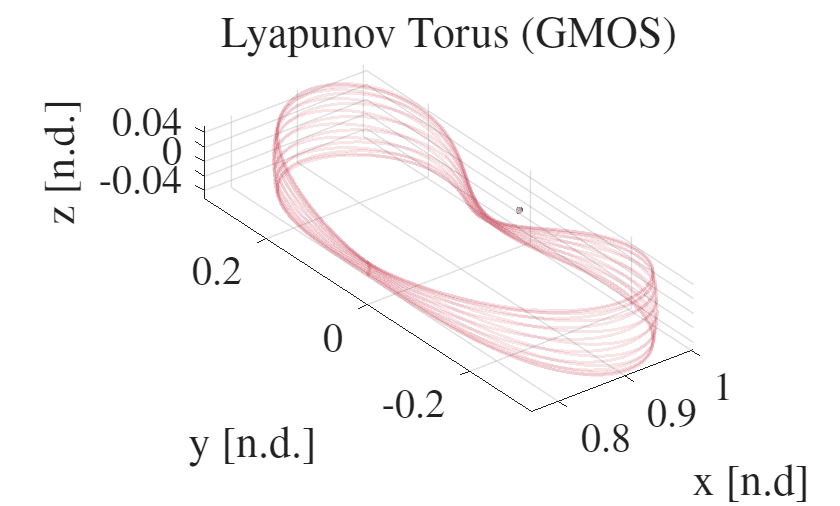


k = numel(fam.z);           % last family solution, for example
z = fam.z{40};

% Propagate every ith sample on the curve
jList = 1:3:N;

nPeriods = 1;              % total time = 10*T
nSavePerPeriod = 500;       % smooth curves
ode_opts = odeset('RelTol',1e-13,'AbsTol',1e-13);

traj = gmos_propagate_qpos_orbits(z, N, mu_EM_JPL, jList, nPeriods, nSavePerPeriod, ode_opts); 


% Color by index (different colors), opaque
%gmos_plot_qpos_orbits_3d(traj, struct('mode','index','alpha',1,'lineWidth',1.0));

% % Gray with transparency
% gmos_plot_qpos_orbits_3d(traj, struct('mode','gray','gray',0.2,'alpha',0.15,'lineWidth',1.0));
% 
 % Single custom RGB color with transparency (e.g., teal)
 gmos_plot_qpos_orbits_3d(traj, struct('mode','rgb','rgb',[0.7 0.0 0.1],'alpha',0.1,'lineWidth',1.5));
 plot_Moon_nd(1e3,1,1);
% plot_Earth_nd(1e3,1,1)
 title('Lyapunov Torus (GMOS)')

[X0,T,rho] = gmos_unpack_z(z_sol, N);
r = X0(1:3,:);
fprintf('range x: [%.3g, %.3g]\n', min(r(1,:)), max(r(1,:)));

range x: [0.759, 0.759]


fprintf('range y: [%.3g, %.3g]\n', min(r(2,:)), max(r(2,:)));

range y: [-7.09e-20, 7.1e-20]


fprintf('range z: [%.3g, %.3g]\n', min(r(3,:)), max(r(3,:)));

range z: [-1.2e-07, 1.2e-07]


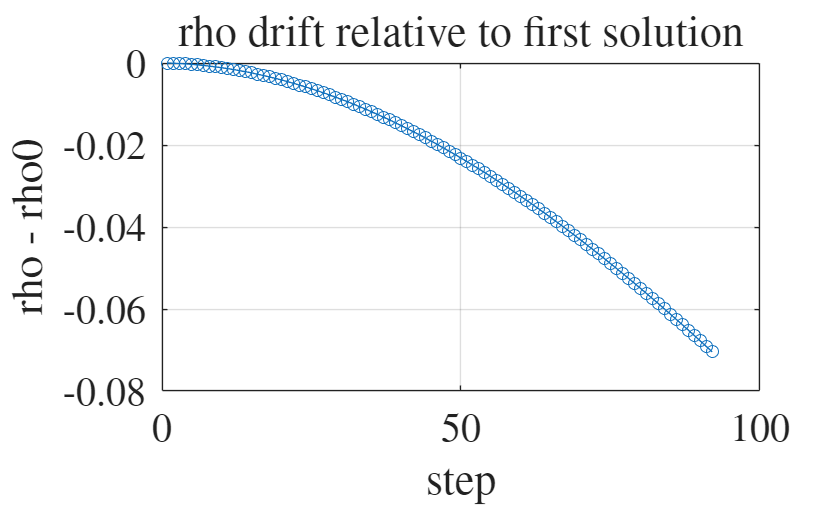

rho0 = fam.rho(1);
figure; plot(fam.rho - rho0, 'o-'); grid on;
xlabel('step'); ylabel('rho - rho0');
title('rho drift relative to first solution');

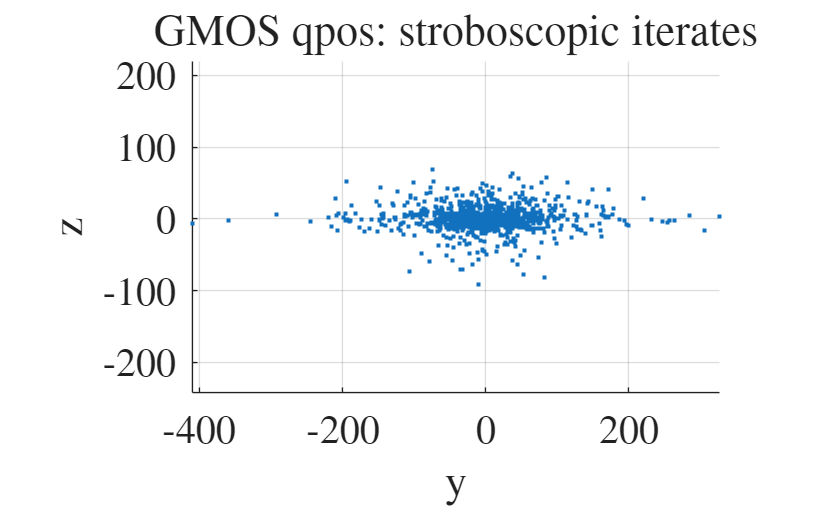

 
ode_opts = odeset('RelTol',1e-12,'AbsTol',1e-12);

step = numel(fam.z);      % last family member (for example)
nIter = 40;               % torus filling density

qpos = gmos_generate_qpos_iterates(fam.z{step}, N, mu_EM_JPL, nIter, ode_opts);
gmos_plot_qpos_points(qpos, 'yz');

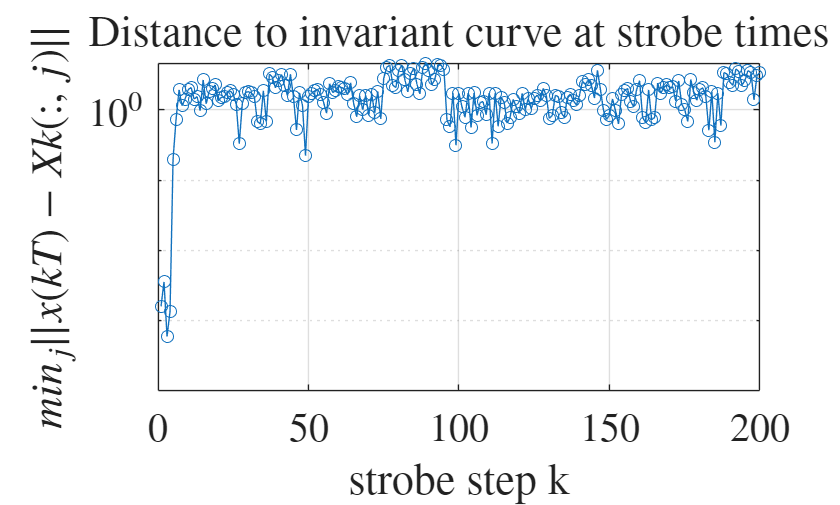

[X0, T, rho] = gmos_unpack_z(z, N);

j0 = 1;
x = X0(:,j0);

nSteps = 200;
errMin = zeros(nSteps,1);

for k = 1:nSteps
    sol = ode113(@(t,y) CR3BP_mu(t,y,mu_EM_JPL), [0,T], x, ode_opts);
    x = sol.y(:,end);

    % Compare to the curve shifted by k*rho
    Xk = gmos_shift_curve_fft(X0, k*rho);

    % Distance to the curve (discrete min)
    diffs = Xk - x;
    d2 = sum(diffs.^2, 1);
    errMin(k) = sqrt(min(d2));
end

figure; semilogy(errMin,'o-'); grid on;
xlabel('strobe step k'); ylabel('$min_j ||x(kT) - Xk(:,j)||$');
title('Distance to invariant curve at strobe times');

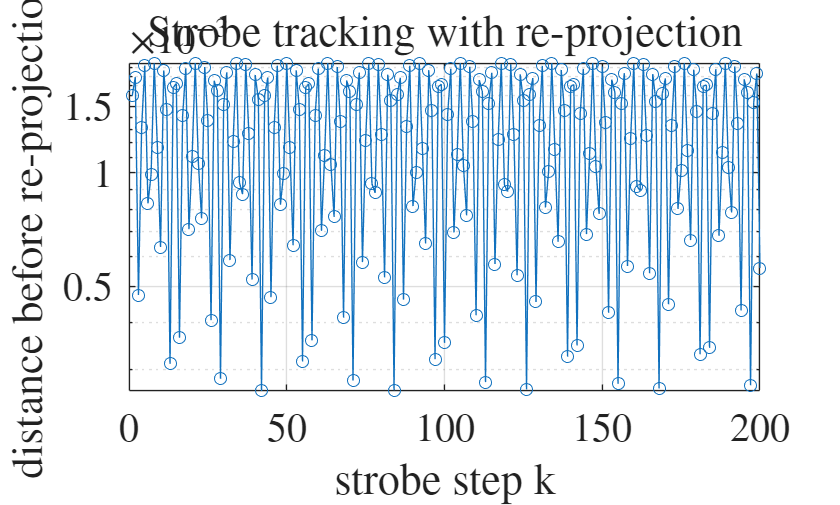

[X0, T, rho] = gmos_unpack_z(z, N);

x = X0(:,1);
nSteps = 200;
err = zeros(nSteps,1);

for k = 1:nSteps
    sol = ode113(@(t,y) CR3BP_mu(t,y,mu_EM_JPL), [0,T], x, ode_opts);
    x = sol.y(:,end);

    Xk = gmos_shift_curve_fft(X0, k*rho);

    diffs = Xk - x;
    d2 = sum(diffs.^2, 1);
    [err(k), jmin] = min(d2);
    err(k) = sqrt(err(k));

    % re-project (shadowing)
    x = Xk(:, jmin);
end

figure; semilogy(err,'o-'); grid on;
xlabel('strobe step k'); ylabel('distance before re-projection');
title('Strobe tracking with re-projection');


beep

[EGMOS, delta] = gmos_accuracy_test_paper(z_sol, N, mu_EM_JPL, ode_opts);
fprintf('Paper accuracy EGMOS = %.3e\n', EGMOS);

Paper accuracy EGMOS = 5.422e-11


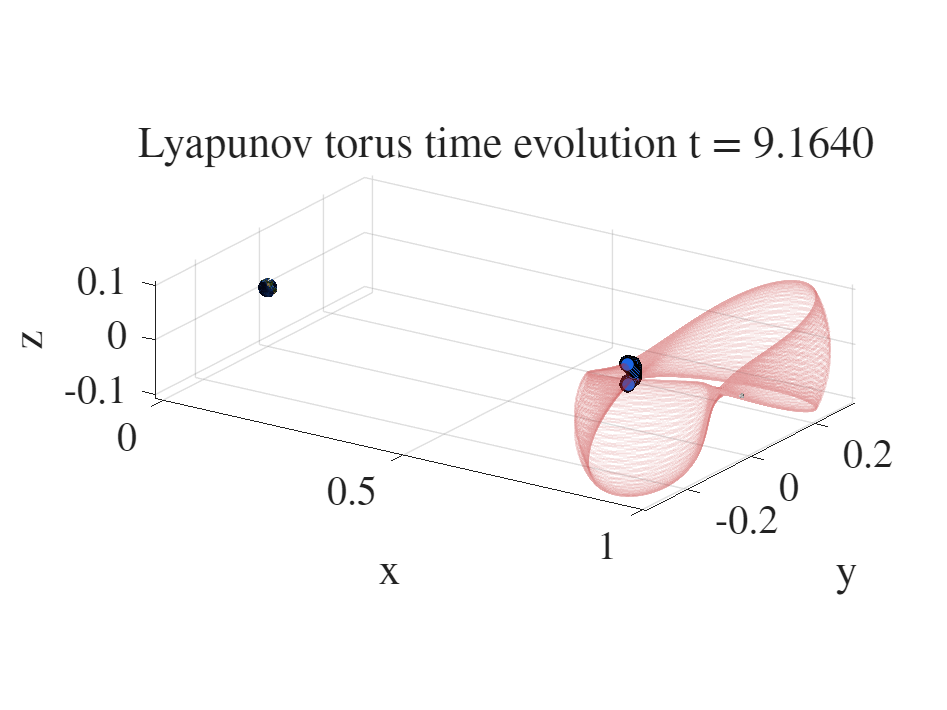

% ------------------------------------------------------------
% Animate one Lyapunov torus with moving particles
% and a constantly rotating camera
% ------------------------------------------------------------
fam_lyap=fam;
% Example: choose one Lyapunov torus solution
z = fam_lyap.z{end};   % replace with your Lyapunov family variable if needed

jList = 1:1:N;
nPeriods = 2;
nSavePerPeriod = 400;

traj = gmos_propagate_qpos_orbits( ...
    z, N, mu_EM_JPL, jList, nPeriods, nSavePerPeriod, ode_opts);

Y = traj.Y;                      % 6 x K x M
[~, K, M] = size(Y);

if isfield(traj, 't')
    tvec = traj.t;
elseif isfield(traj, 'tout')
    tvec = traj.tout;
else
    tvec = 1:K;
end

% Animation settings
frameStride = 3;
fps = 20;
outFile = 'gmos_lyapunov_torus_animation.mp4';

az0 = 35;
el0 = 20;
markerSize = 45;

fig = figure('Color','w','Position',[100 100 1200 900]);
ax = axes(fig);
hold(ax,'on');
grid(ax,'on');
axis(ax,'equal');
view(ax, az0, el0);
xlabel(ax,'x');
ylabel(ax,'y');
zlabel(ax,'z');
title(ax,'Lyapunov torus time evolution');

% Plot faint background torus
for m = 1:M
    r = squeeze(Y(1:3,:,m));
    patch(ax, ...
        'XData', [r(1,:) nan], ...
        'YData', [r(2,:) nan], ...
        'ZData', [r(3,:) nan], ...
        'FaceColor', 'none', ...
        'EdgeColor', [0.75 0.15 0.15], ...
        'EdgeAlpha', 0.08, ...
        'LineWidth', 1.0);
end

% Fix axis limits once
xmin = min(Y(1,:,:), [], 'all'); xmax = max(Y(1,:,:), [], 'all');
ymin = min(Y(2,:,:), [], 'all'); ymax = max(Y(2,:,:), [], 'all');
zmin = min(Y(3,:,:), [], 'all'); zmax = max(Y(3,:,:), [], 'all');

dx = xmax - xmin; dy = ymax - ymin; dz = zmax - zmin;
pad = 0.08 * max([dx dy dz]);

xlim(ax, [xmin-pad, xmax+pad]);
ylim(ax, [ymin-pad, ymax+pad]);
zlim(ax, [zmin-pad, zmax+pad]);

% Earth and Moon
plot_Earth_nd(1e3,60,1);
plot_Moon_nd(1e3,60,1);

% Initial simultaneous ring
x = squeeze(Y(1,1,:));
y = squeeze(Y(2,1,:));
zring = squeeze(Y(3,1,:));

hRing = plot3(ax, [x; x(1)], [y; y(1)], [zring; zring(1)], ...
    '-', 'Color', [0.85 0.1 0.1], 'LineWidth', 1.5);

hPts = scatter3(ax, x, y, zring, markerSize, ...
    'filled', ...
    'MarkerFaceColor', [0.1 0.4 0.9], ...
    'MarkerEdgeColor', 'k');

% Video writer
v = VideoWriter(outFile, 'MPEG-4');
v.FrameRate = fps;
open(v);

frameIdx = 1:frameStride:K;
nFrames = numel(frameIdx);

for ii = 1:nFrames
    k = frameIdx(ii);

    x = squeeze(Y(1,k,:));
    y = squeeze(Y(2,k,:));
    zring = squeeze(Y(3,k,:));

    set(hPts, 'XData', x, 'YData', y, 'ZData', zring);
    set(hRing, 'XData', [x; x(1)], 'YData', [y; y(1)], 'ZData', [zring; zring(1)]);

    % Constant camera rotation
    az = az0 + 360*(ii-1)/nFrames;
    view(ax, az, el0);

    if numel(tvec) == K
        title(ax, sprintf('Lyapunov torus time evolution   t = %.4f', tvec(k)));
    else
        title(ax, sprintf('Lyapunov torus time evolution   frame = %d', k));
    end

    drawnow;
    writeVideo(v, getframe(fig));
end


close(v);
fprintf('Saved animation to %s\n', outFile);

Saved animation to gmos_lyapunov_torus_animation.mp4


DRO Paper Example

% clear 
% clc

set(0,'DefaultFigureWindowStyle','normal');

set(groot,'DefaultTextInterpreter','latex');
set(groot,'DefaultAxesTickLabelInterpreter','latex');
set(groot,'DefaultLegendInterpreter','latex');
set(groot,'DefaultAxesFontSize',26);
set(groot,'DefaultTextFontSize',28);

% -------------------------
% Constants
% -------------------------
mu_EM_JPL = 1.215058560962404e-2;


mu= mu_EM_JPL

mu = 0.0122

orbit_index=300

orbit_index = 300


po = pick_po_from_JPL('DRO_orbits_JPL_IC_Earth_Moon.csv', orbit_index);  % your DRO file
xPO0 = po.x0(:);
TPO  = po.T;

% Enforce planar subspace
xPO0(3) = 0; xPO0(6) = 0;

ode_opts = odeset('RelTol',1e-12,'AbsTol',1e-12);



sol = ode89(@(t,y) CR3BP_mu(t,y,mu), [0,TPO], xPO0, ode_opts);
fprintf('DRO closure error = %.3e\n', norm(sol.y(:,end)-xPO0));

DRO closure error = 4.603e-13



% 
% figure;
% hold on
% axis equal
% grid on
% title('Chosen DRO')
% xlabel('x [n.d]')
% plot3(Y_eval(1,:),Y_eval(2,:),Y_eval(3,:))
% %scatter3(sol.y(1,1),sol.y(2,1),sol.y(3,1))
% scatter3(Y_eval(1,1e3),Y_eval(2,1e3),Y_eval(3,1e3))

N = 25;                 % paper style
K = 1e-5;               % small amplitude
Ttarget = TPO;

demo = gmos_demo_invariance_only(mu, xPO0, TPO, N, K, false, 'planar');

Mode: planar
Eigenvector projections: planar 1.000e+00, vertical 4.909e-18
Init amplitude [x y z xd yd zd] = [2.19e-06 1.95e-05 9.79e-23 1.53e-06 3.24e-06 0.00e+00]
Max init amplitude: component 2, amp = 1.948e-05
Linearization test at j=1:
  ||dx0||      = 9.806e-06
  ||dx1||      = 6.627e-06
  ||dx1_lin||  = 6.632e-06
  ||dx1-dx1lin|| = 5.769e-09
Inf residual: +rho 5.363e-09, -rho 1.469e-05, using sign 1
||Finv||2   = 1.750e-08
||Finv||inf = 5.363e-09


init = demo.init;

% Use init as reference (paper)
Xref   = init.X0;
Tref   = init.T0;
rhoref = init.rho0;

z0 = gmos_pack_z(init.X0, init.T0, init.rho0);

optsN = struct('maxIter', 8, 'tolInf', 1e-10, 'verbose', true);
[z_sol, info] = gmos_newton_fixT_analytic(z0, N, mu, Xref, Tref, rhoref, Ttarget, ode_opts, optsN);

Newton iter  1: ||F||inf = 5.363e-09, ||F||2 = 1.750e-08
Newton iter  2: ||F||inf = 3.386e-14, ||F||2 = 7.484e-14


[X0, T, rho] = gmos_unpack_z(z_sol, N);

figure; hold on; grid on; axis equal;
plot(X0(1,:), X0(2,:), 'o-');
xlabel('x'); ylabel('y');
title(sprintf('Invariant curve (x-y), N=%d', N));

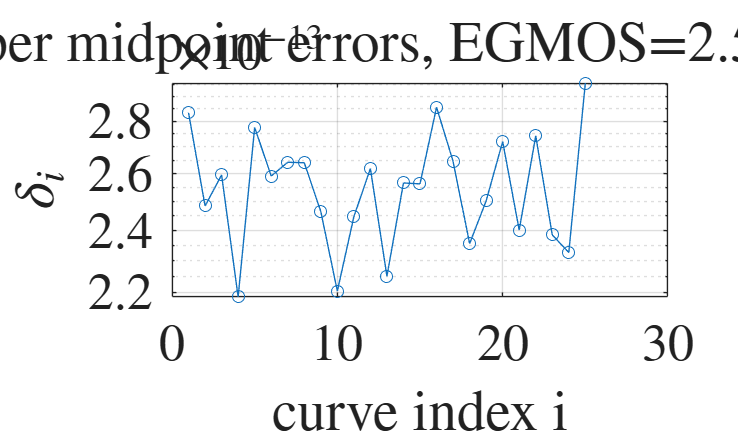

[EGMOS, delta] = gmos_accuracy_test_paper(z_sol, N, mu_EM_JPL, ode_opts);

figure; semilogy(1:N, delta, 'o-'); grid on;
xlabel('curve index i'); ylabel('$\delta_i$');
title(sprintf('Paper midpoint errors, EGMOS=%.3e', EGMOS));

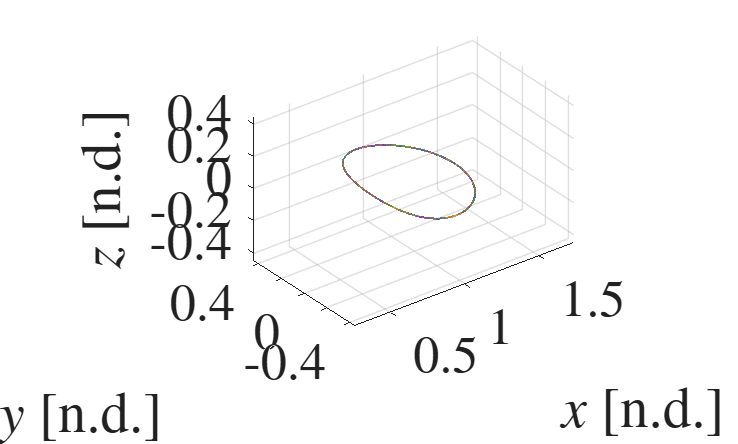

jList = 1:5:N;
nPeriods = 5;
nSavePerPeriod = 200;

traj = gmos_propagate_qpos_orbits(z_sol, N, mu_EM_JPL, jList, nPeriods, nSavePerPeriod, ode_opts);
gmos_plot_qpos_orbits_3d(traj, struct('mode','index','alpha',0.4,'lineWidth',1.0));

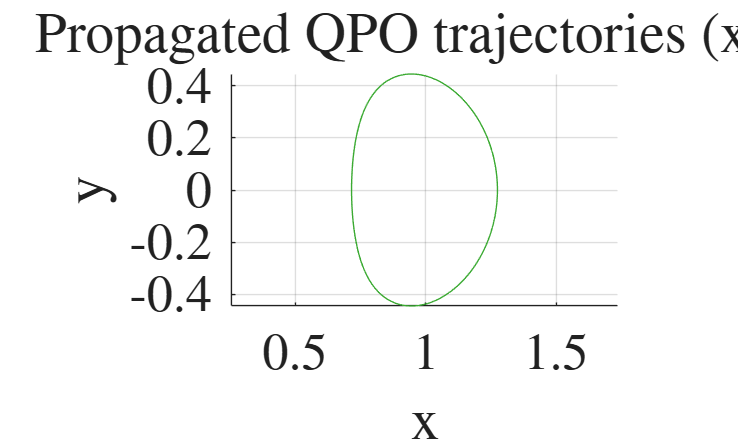

figure; hold on; grid on; axis equal;
for m = 1:numel(jList)
    r = squeeze(traj.Y(1:3,:,m));
    plot(r(1,:), r(2,:), '-');
end
xlabel('x'); ylabel('y');
title('Propagated QPO trajectories (x-y)');

[EGMOS, delta] = gmos_accuracy_test_paper(z_sol, N, mu, ode_opts);
fprintf('Paper accuracy EGMOS = %.3e, max(delta)=%.3e\n', EGMOS, max(delta));

Paper accuracy EGMOS = 2.558e-13, max(delta)=2.954e-13


N2 = 51;

demo2 = gmos_demo_invariance_only(mu, xPO0, TPO, N2, K, false, 'planar');

Mode: planar
Eigenvector projections: planar 1.000e+00, vertical 4.909e-18
Init amplitude [x y z xd yd zd] = [2.19e-06 1.95e-05 9.81e-23 1.53e-06 3.25e-06 0.00e+00]
Max init amplitude: component 2, amp = 1.953e-05
Linearization test at j=1:
  ||dx0||      = 9.806e-06
  ||dx1||      = 6.627e-06
  ||dx1_lin||  = 6.632e-06
  ||dx1-dx1lin|| = 5.769e-09
Inf residual: +rho 5.380e-09, -rho 1.470e-05, using sign 1
||Finv||2   = 2.500e-08
||Finv||inf = 5.380e-09


init2 = demo2.init;

Xref2   = init2.X0;
Tref2   = init2.T0;
rhoref2 = init2.rho0;

z02 = gmos_pack_z(init2.X0, init2.T0, init2.rho0);

[z_sol2, ~] = gmos_newton_fixT_analytic(z02, N2, mu, Xref2, Tref2, rhoref2, Ttarget, ode_opts, optsN);

Newton iter  1: ||F||inf = 5.380e-09, ||F||2 = 2.500e-08
Newton iter  2: ||F||inf = 6.058e-14, ||F||2 = 2.552e-13



[EGMOS2, ~] = gmos_accuracy_test_paper(z_sol2, N2, mu, ode_opts);

fprintf('EGMOS N=25: %.3e\n', EGMOS);

EGMOS N=25: 2.558e-13


fprintf('EGMOS N=51: %.3e\n', EGMOS2);

EGMOS N=51: 2.758e-13


%DRO FAMILY
% 
% 
% clear
% clc



% -------------------------
% Constants
% -------------------------
mu_EM_JPL = 1.215058560962404e-2;

mu=mu_EM_JPL

mu = 0.0122

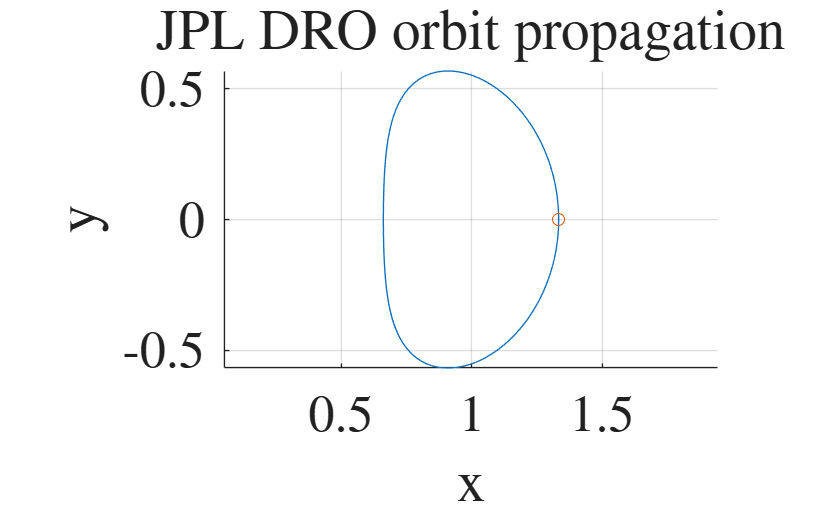


orbit_index = 330;

po = pick_po_from_JPL('DRO_orbits_JPL_IC_Earth_Moon.csv', orbit_index);
xPO0 = po.x0(:);
TPO  = po.T;


[t_eval, Y_eval] = IntegrateCR3BP_ODE89(xPO0, [0,TPO], mu, 2e3);

Y_eval=Y_eval';



xPO0 = Y_eval(:,1e3);

% -------------------------
% Quick trajectory plot (optional)
% -------------------------
[t_eval, Y_eval] = IntegrateCR3BP_ODE89(xPO0, [0, TPO], mu_EM_JPL, 1e3);

figure;
hold on; grid on; axis equal;
plot3(Y_eval(:,1), Y_eval(:,2), Y_eval(:,3));
scatter3(Y_eval(1,1), Y_eval(1,2), Y_eval(1,3));
xlabel('x'); ylabel('y'); zlabel('z');
title('JPL DRO orbit propagation');


max(Y_eval(1,:))

ans = 1.3325



% xPO0(3) = 0;
% xPO0(6) = 0;

ode_opts = odeset('RelTol',1e-12,'AbsTol',1e-12);

sol = ode89(@(t,y) CR3BP_mu(t,y,mu), [0, TPO], xPO0, ode_opts);
fprintf('DRO closure error = %.3e\n', norm(sol.y(:,end) - xPO0));

DRO closure error = 5.033e-13



N = 51;
Ttarget = TPO;
mode = 'planar';

K0 = 5e-5;
K1 = 7e-5;

demo0 = gmos_demo_invariance_only(mu, xPO0, TPO, N, K0, false, mode);

Mode: planar
Eigenvector projections: planar 1.000e+00, vertical 1.869e-25
Init amplitude [x y z xd yd zd] = [2.41e-05 8.29e-05 1.72e-29 4.43e-05 2.40e-05 7.18e-30]
Max init amplitude: component 2, amp = 8.286e-05
Linearization test at j=1:
  ||dx0||      = 4.702e-05
  ||dx1||      = 2.665e-05
  ||dx1_lin||  = 2.665e-05
  ||dx1-dx1lin|| = 6.089e-09
Inf residual: +rho 6.634e-09, -rho 7.332e-05, using sign 1
||Finv||2   = 4.010e-08
||Finv||inf = 6.634e-09


demo1 = gmos_demo_invariance_only(mu, xPO0, TPO, N, K1, false, mode);

Mode: planar
Eigenvector projections: planar 1.000e+00, vertical 1.869e-25
Init amplitude [x y z xd yd zd] = [3.37e-05 1.16e-04 2.41e-29 6.20e-05 3.36e-05 1.00e-29]
Max init amplitude: component 2, amp = 1.160e-04
Linearization test at j=1:
  ||dx0||      = 6.583e-05
  ||dx1||      = 3.732e-05
  ||dx1_lin||  = 3.731e-05
  ||dx1-dx1lin|| = 1.193e-08
Inf residual: +rho 1.300e-08, -rho 1.027e-04, using sign 1
||Finv||2   = 7.858e-08
||Finv||inf = 1.300e-08



init0 = demo0.init;
init1 = demo1.init;

Xref   = init0.X0;
Tref   = init0.T0;
rhoref = init0.rho0;

z0 = gmos_pack_z(init0.X0, init0.T0, init0.rho0);
z1 = gmos_pack_z(init1.X0, init1.T0, init1.rho0);

optsN = struct('maxIter',16,'tolInf',1e-10,'verbose',true);

[z0_sol, info0] = gmos_newton_fixT_analytic( ...
    z0, N, mu, Xref, Tref, rhoref, Ttarget, ode_opts, optsN);

Newton iter  1: ||F||inf = 6.634e-09, ||F||2 = 4.010e-08
Newton iter  2: ||F||inf = 3.285e-14, ||F||2 = 1.158e-13



[z1_sol, info1] = gmos_newton_fixT_analytic( ...
    z1, N, mu, Xref, Tref, rhoref, Ttarget, ode_opts, optsN);

Newton iter  1: ||F||inf = 1.300e-08, ||F||2 = 7.859e-08
Newton iter  2: ||F||inf = 3.486e-13, ||F||2 = 1.845e-12



fprintf('seed 0 final ||F||inf = %.3e\n', info0.normInf(end));

seed 0 final ||F||inf = 3.285e-14


fprintf('seed 1 final ||F||inf = %.3e\n', info1.normInf(end));

seed 1 final ||F||inf = 3.486e-13



% ds = 1e-3;
% nSteps = 200;  %FINE STEPS


ds = 0.4e-2;
nSteps = 50;

if isfile('fam_fixT_DRO_Paper_like.mat')
    load('fam_fixT_DRO_Paper_like.mat','fam')
else
    fam = gmos_continue_fixT_family( ...
        z0_sol, z1_sol, nSteps, ds, N, mu, Ttarget, ode_opts, optsN);
    save('fam_fixT_DRO_Paper_like.mat','fam')
end

Newton iter  1: ||F||inf = 1.705e-06, ||F||2 = 1.031e-05
Newton iter  2: ||F||inf = 1.308e-10, ||F||2 = 5.659e-10
Newton iter  3: ||F||inf = 2.250e-14, ||F||2 = 8.193e-14
Continuation step 1/50: T = 5.227797973250643, rho = 2.057241219296049, final ||F||inf = 2.250e-14
Newton iter  1: ||F||inf = 3.349e-06, ||F||2 = 2.013e-05
Newton iter  2: ||F||inf = 5.013e-10, ||F||2 = 2.158e-09
Newton iter  3: ||F||inf = 3.564e-14, ||F||2 = 9.232e-14
Continuation step 2/50: T = 5.227797973250643, rho = 2.057267511258123, final ||F||inf = 3.564e-14
Newton iter  1: ||F||inf = 3.400e-06, ||F||2 = 2.013e-05
Newton iter  2: ||F||inf = 5.061e-10, ||F||2 = 2.167e-09
Newton iter  3: ||F||inf = 2.691e-14, ||F||2 = 8.296e-14
Continuation step 3/50: T = 5.227797973250643, rho = 2.057310396076954, final ||F||inf = 2.691e-14
Newton iter  1: ||F||inf = 3.453e-06, ||F||2 = 2.013e-05
Newton iter  2: ||F||inf = 5.124e-10, ||F||2 = 2.182e-09
Newton iter  3: ||F||inf = 2.746e-14, ||F||2 = 1.035e-13
Continuation step 4


beep

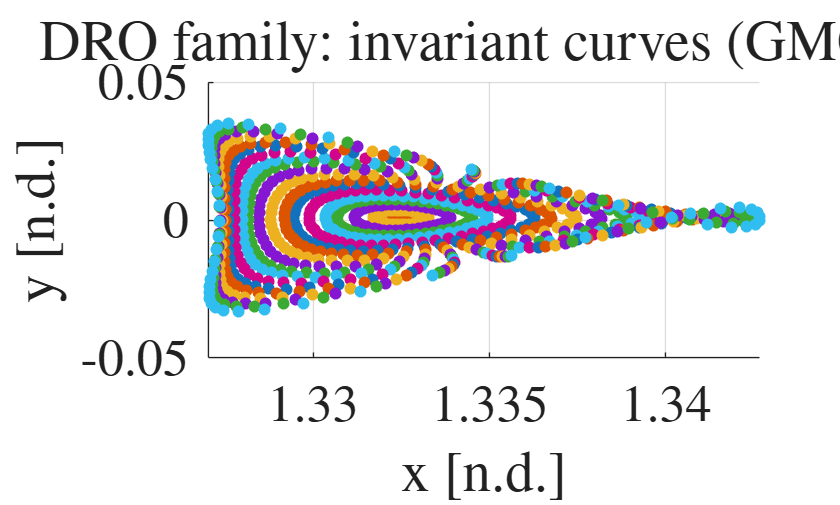


idxList = unique(round(linspace(1, numel(fam.z), min(20, numel(fam.z)))));


figure
hold on
grid on
%axis equal

for ii = idxList(:).'
    [X0i, ~, ~] = gmos_unpack_z(fam.z{ii}, N);
    scatter(X0i(1,:), X0i(2,:) ,'filled'  )
end
xlabel('x [n.d.]')
ylabel('y [n.d.]')
title('DRO family: invariant curves (GMOS)')


z = fam.z{end};

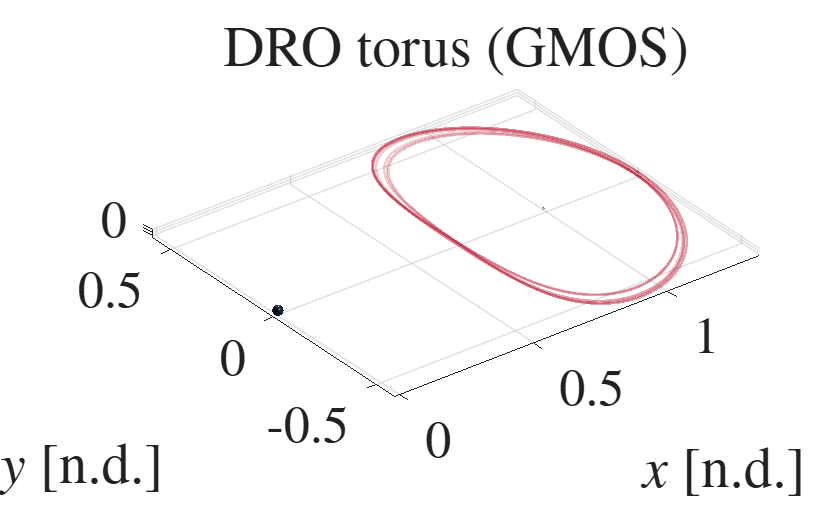


jList = 1:6:N;
nPeriods = 1;
nSavePerPeriod = 200;

traj = gmos_propagate_qpos_orbits( ...
    z, N, mu, jList, nPeriods, nSavePerPeriod, ode_opts);




gmos_plot_qpos_orbits_3d( ...
    traj, struct('mode','rgb','rgb',[0.7 0.0 0.1],'alpha',0.2,'lineWidth',1.2));
plot_Moon_nd(1e3,1,1);
plot_Earth_nd(1e3,1,1);

title('DRO torus (GMOS)')



[EGMOS_end, delta_end] = gmos_accuracy_test_paper(z, N, mu, ode_opts);
fprintf('Last family member: EGMOS = %.3e, max(delta) = %.3e\n', EGMOS_end, max(delta_end));

Last family member: EGMOS = 3.026e-09, max(delta) = 5.706e-09


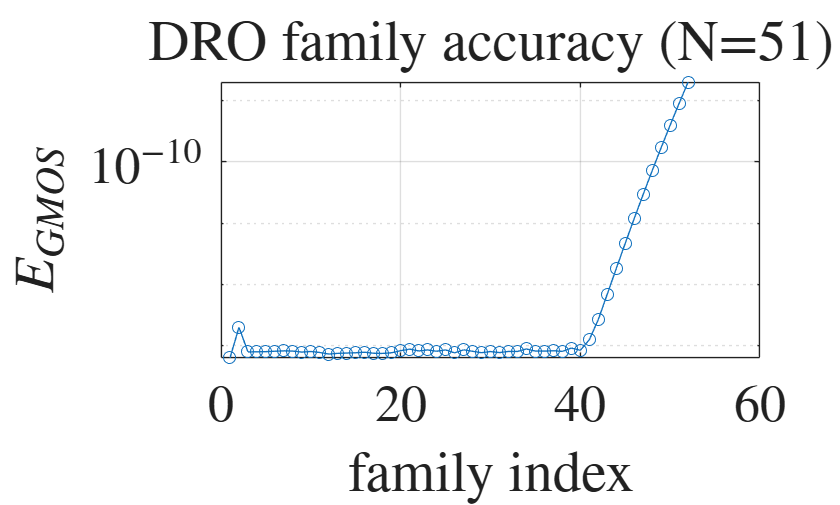


EG = nan(numel(fam.z),1);
parfor k = 1:numel(fam.z)
    [EG(k), ~] = gmos_accuracy_test_paper(fam.z{k}, N, mu, ode_opts);
end

figure
semilogy(1:numel(EG), EG, 'o-')
grid on
xlabel('family index')
ylabel('$E_{GMOS}$')
title('DRO family accuracy (N=51)')

HALO QPOs

clear
clc

% =========================================================
% Minimal GMOS halo script
% =========================================================

% -------------------------
% Constants
% -------------------------

mu_EM_JPL = 1.215058560962404e-2;

mu = mu_EM_JPL;
ode_opts = odeset('RelTol',1e-12,'AbsTol',1e-12);

% -------------------------
% Pick one halo orbit from JPL
% -------------------------
%orbit_index = 896;

orbit_index = 200;
po = pick_po_from_JPL('L1_northern_halo_orbits_JPL_IC_Earth_Moon.csv', orbit_index);

xPO0 = po.x0;
TPO  = po.T;

fprintf('Using halo orbit index %d\n', orbit_index);

Using halo orbit index 200


fprintf('TPO = %.15f\n', TPO);

TPO = 1.949498846364953


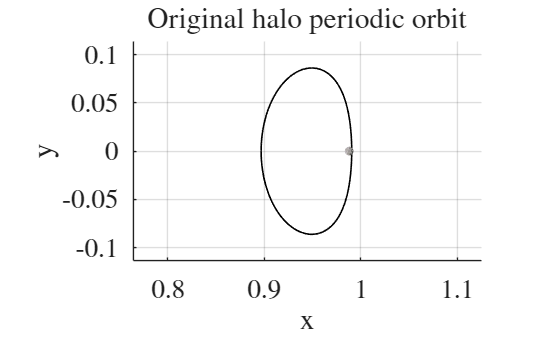


% -------------------------
% Plot the periodic orbit itself
% -------------------------
[t_eval, Y_eval] = IntegrateCR3BP_ODE89(xPO0, [0, TPO], mu, 1000);

figure;
hold on; grid on; axis equal;
plot3(Y_eval(:,1), Y_eval(:,2), Y_eval(:,3), 'k', 'LineWidth', 1.2);
plot_Moon_nd(1e3,1,1);
xlabel('x'); ylabel('y'); zlabel('z');
title('Original halo periodic orbit');


% -------------------------
% Periodic orbit closure check
% -------------------------
solPO = ode89(@(t,Y) CR3BP_mu(t,Y,mu), [0, TPO], xPO0, ode_opts);
x_end = solPO.y(:,end);
fprintf('PO closure error = %.3e\n', norm(x_end - xPO0));

PO closure error = 2.719e-13



% -------------------------
% Monodromy eigenvalues
% -------------------------
M_eigs = monodromy_CR3BP([0, TPO], xPO0, mu);
V = M_eigs(:,1:6);
D = M_eigs(:,7:12);
lam = diag(D);

fprintf('\nMonodromy eigenvalues:\n');


Monodromy eigenvalues:


disp(lam)

  -3.5274 + 0.0000i
  -0.2835 + 0.0000i
   1.0000 + 0.0000i
   1.0000 - 0.0000i
   0.7885 + 0.6151i
   0.7885 - 0.6151i



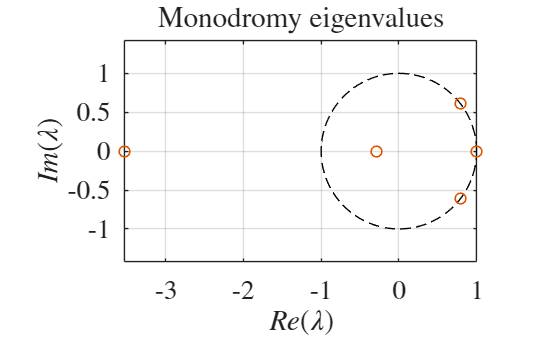


figure;
th = linspace(0, 2*pi, 400);
plot(cos(th), sin(th), 'k--'); hold on; grid on; axis equal;
plot(real(lam), imag(lam), 'o', 'MarkerSize', 8, 'LineWidth', 1.2);
xlabel('$Re(\lambda)$');
ylabel('$Im(\lambda)$');
title('Monodromy eigenvalues');


% -------------------------
% Choose the relevant center mode and K
% -------------------------
% Start with one mode, then switch if the projection printout suggests otherwise
mode = 'vertical';   % try 'vertical' first, then 'planar' if needed
N    = 51;
K    = 1e-2;         % first try very small, then increase gradually

cen = gmos_center_eigpair_from_monodromy([0, TPO], xPO0, mu, mode);

fprintf('\nChosen mode: %s\n', mode);


Chosen mode: vertical


fprintf('Selected lambda = %.15f %+ .15fi\n', real(cen.lambda), imag(cen.lambda));

Selected lambda = 0.788450125086418 +0.615098691471608i


fprintf('rho0 = %.15f\n', cen.rho0);

rho0 = 0.662511131874830


fprintf('planar projection   = %.3e\n', cen.proj.planar);

planar projection   = 5.441e-01


fprintf('vertical projection = %.3e\n', cen.proj.vertical);

vertical projection = 8.390e-01


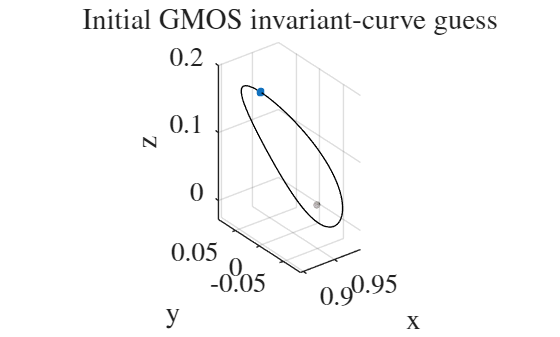


% -------------------------
% Build the initial invariant-curve guess
% -------------------------
init = gmos_init_curve_from_center_mode(xPO0, TPO, cen, N, K, false);

figure;
scatter3(init.X0(1,:), init.X0(2,:), init.X0(3,:), 18, 'filled');
hold on; grid on; axis equal;
plot3(Y_eval(:,1), Y_eval(:,2), Y_eval(:,3), 'k', 'LineWidth', 1.0);
plot_Moon_nd(1e3,1,1);
xlabel('x'); ylabel('y'); zlabel('z');
title('Initial GMOS invariant-curve guess');


% -------------------------
% Initial invariance diagnostic
% -------------------------
demo = gmos_demo_invariance_only(mu, xPO0, TPO, N, K, false, mode);

Mode: vertical
Eigenvector projections: planar 5.441e-01, vertical 8.390e-01
Init amplitude [x y z xd yd zd] = [3.10e-03 3.92e-03 2.32e-03 5.99e-03 7.57e-03 1.66e-02]
Max init amplitude: component 6, amp = 1.660e-02
Linearization test at j=1:
  ||dx0||      = 9.051e-03
  ||dx1||      = 7.239e-03
  ||dx1_lin||  = 7.600e-03
  ||dx1-dx1lin|| = 7.948e-04
Inf residual: +rho 4.873e-04, -rho 1.031e-02, using sign 1
||Finv||2   = 3.588e-03
||Finv||inf = 4.873e-04


fprintf('\nInitial invariance diagnostic:\n');


Initial invariance diagnostic:


fprintf('||Finv||2   = %.3e\n', demo.norm2);

||Finv||2   = 3.588e-03


fprintf('||Finv||inf = %.3e\n', demo.normInf);

||Finv||inf = 4.873e-04



% -------------------------
% Newton solve with fixed T = TPO
% -------------------------
Xref   = init.X0;
Tref   = init.T0;
rhoref = init.rho0;
z0     = gmos_pack_z(init.X0, init.T0, init.rho0);

optsN = struct();
optsN.maxIter = 12;
optsN.tolInf  = 1e-10;
optsN.verbose = true;

tic

[z_sol, info] = gmos_newton_fixT_analytic( ...
    z0, N, mu, Xref, Tref, rhoref, TPO, ode_opts, optsN);

Newton iter  1: ||F||inf = 4.873e-04, ||F||2 = 3.588e-03
Newton iter  2: ||F||inf = 1.110e-06, ||F||2 = 5.333e-06
Newton iter  3: ||F||inf = 3.181e-07, ||F||2 = 2.283e-06
Newton iter  4: ||F||inf = 1.432e-12, ||F||2 = 1.048e-11



toc

Elapsed time is 1.476088 seconds.



[X0_sol, T_sol, rho_sol] = gmos_unpack_z(z_sol, N);

fprintf('\nSolved torus:\n');


Solved torus:


fprintf('T   = %.15f\n', T_sol);

T   = 1.949498846364953


fprintf('rho = %.15f\n', rho_sol);

rho = 0.662011992850977


fprintf('final ||F||inf = %.3e\n', info.normInf(end));

final ||F||inf = 1.432e-12


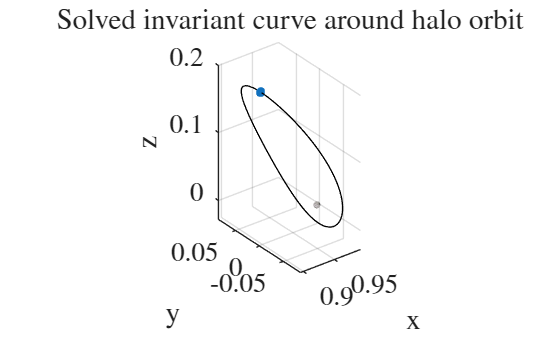


% -------------------------
% Plot the solved invariant curve
% -------------------------
figure;
scatter3(X0_sol(1,:), X0_sol(2,:), X0_sol(3,:), 24, 'filled');
hold on; grid on; axis equal;
plot3(Y_eval(:,1), Y_eval(:,2), Y_eval(:,3), 'k', 'LineWidth', 1.0);
plot_Moon_nd(1e3,1,1);
xlabel('x'); ylabel('y'); zlabel('z');
title('Solved invariant curve around halo orbit');

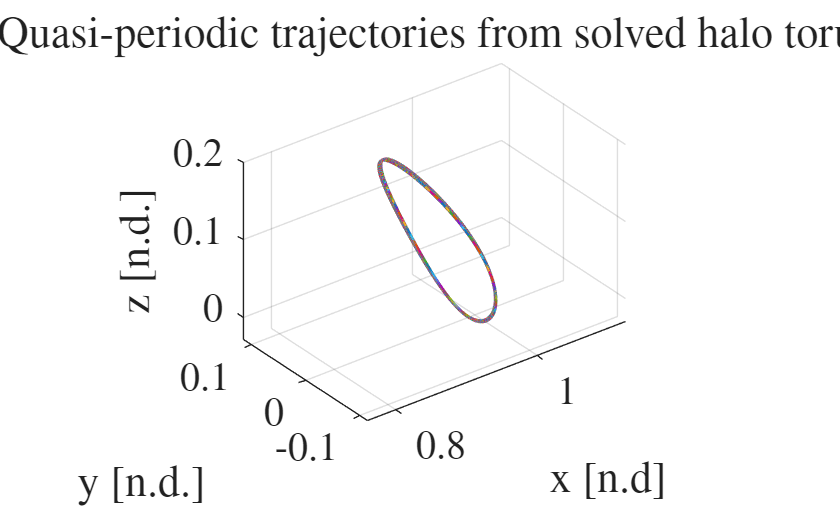


% -------------------------
% Propagate representative trajectories on the torus
% -------------------------
jList = 1:1:N;
nPeriods = 3;
nSavePerPeriod = 1000;

traj = gmos_propagate_qpos_orbits( ...
    z_sol, N, mu, jList, nPeriods, nSavePerPeriod, ode_opts);

gmos_plot_qpos_orbits_3d(traj, struct( ...
    'mode','index', ...
    'alpha',1, ...
    'lineWidth',1.0));

title('Quasi-periodic trajectories from solved halo torus');

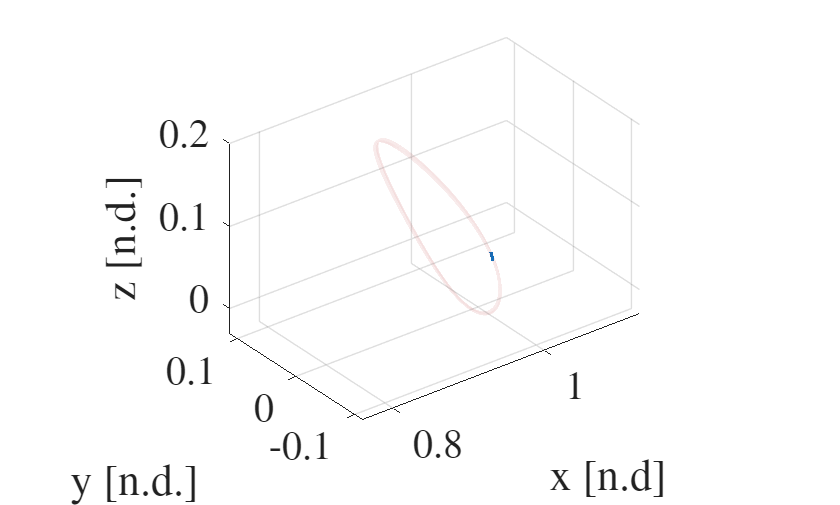



jList = 1:3:N;
traj = gmos_propagate_qpos_orbits(z_sol, N, mu_EM_JPL, jList, 2.1, 300, ode_opts);



gmos_plot_qpos_orbits_3d(traj, struct('mode','rgb','rgb',[0.7 0.0 0.1],'alpha',0.01,'lineWidth',1), 0.65*TPO)

 
plot3(X0(1,:), X0(2,:), X0(3,:), 'ro', 'MarkerSize', 4, 'MarkerFaceColor', 'r')

Unrecognized function or variable 'X0'.

xlabel('x')
ylabel('y')
zlabel('z')
title('Single torus and its invariant curve')

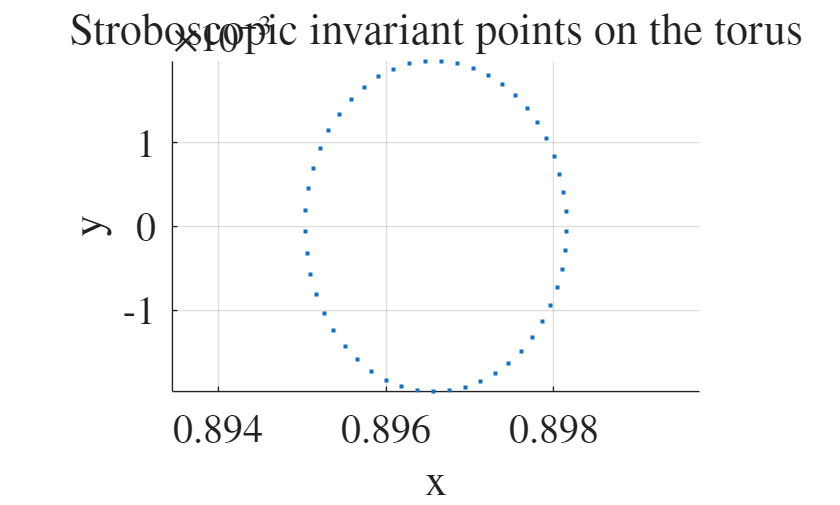


% -------------------------
% Stroboscopic point diagnostic
% -------------------------
nIter = 4;
qpos = gmos_generate_qpos_iterates(z_sol, N, mu, nIter, ode_opts);

figure;
gmos_plot_qpos_points(qpos, 'xy');
title('Stroboscopic invariant points on the torus');


% -------------------------
% Optional paper-style accuracy metric, if available
% -------------------------
if exist('gmos_accuracy_test_paper', 'file') == 2
    [EGMOS, delta] = gmos_accuracy_test_paper(z_sol, N, mu, ode_opts);
    fprintf('EGMOS = %.3e\n', EGMOS);
end

EGMOS = 1.443e-12


% -------------------------------------------------
% HALO TORUS FAMILY
% Assumes xPO0, TPO, mu_EM_JPL already exist
% -------------------------------------------------

ode_opts = odeset('RelTol',1e-12,'AbsTol',1e-12);
Ttarget  = TPO;

Unrecognized function or variable 'TPO'.

mode     = 'vertical';
N        = 51;

% Two nearby seed amplitudes
K0 = 8e-3;
K1 = 1e-2;

demo0 = gmos_demo_invariance_only(mu_EM_JPL, xPO0, TPO, N, K0, false, mode);
demo1 = gmos_demo_invariance_only(mu_EM_JPL, xPO0, TPO, N, K1, false, mode);

init0 = demo0.init;
init1 = demo1.init;

% Use first seed as reference for the two initial Newton solves
Xref   = init0.X0;
Tref   = init0.T0;
rhoref = init0.rho0;

z0 = gmos_pack_z(init0.X0, init0.T0, init0.rho0);
z1 = gmos_pack_z(init1.X0, init1.T0, init1.rho0);

optsN = struct('maxIter',12,'tolInf',1e-10,'verbose',true);

[z0_sol, info0] = gmos_newton_fixT_analytic( ...
    z0, N, mu_EM_JPL, Xref, Tref, rhoref, Ttarget, ode_opts, optsN);

[z1_sol, info1] = gmos_newton_fixT_analytic( ...
    z1, N, mu_EM_JPL, Xref, Tref, rhoref, Ttarget, ode_opts, optsN);

fprintf('seed 0 final ||F||inf = %.3e\n', info0.normInf(end));
fprintf('seed 1 final ||F||inf = %.3e\n', info1.normInf(end));

% Continue the family
ds     = 2e-3;
nSteps = 100;

if isfile('fam_fixT_halo.mat')
    load('fam_fixT_halo.mat','fam')
else
    fam = gmos_continue_fixT_family( ...
        z0_sol, z1_sol, nSteps, ds, N, mu_EM_JPL, Ttarget, ode_opts, optsN);
    save('fam_fixT_halo.mat','fam')
end

% Plot invariant curves from several family members
idxList = unique(round(linspace(1, numel(fam.z), min(10, numel(fam.z)))));

figure
hold on
grid on
axis equal
for ii = idxList(:).'
    [X0, ~, ~] = gmos_unpack_z(fam.z{ii}, N);
    scatter3(X0(1,:), X0(2,:), X0(3,:), 'filled')
end
xlabel('x')
ylabel('y')
zlabel('z')
title('Halo family: invariant curves (GMOS )')

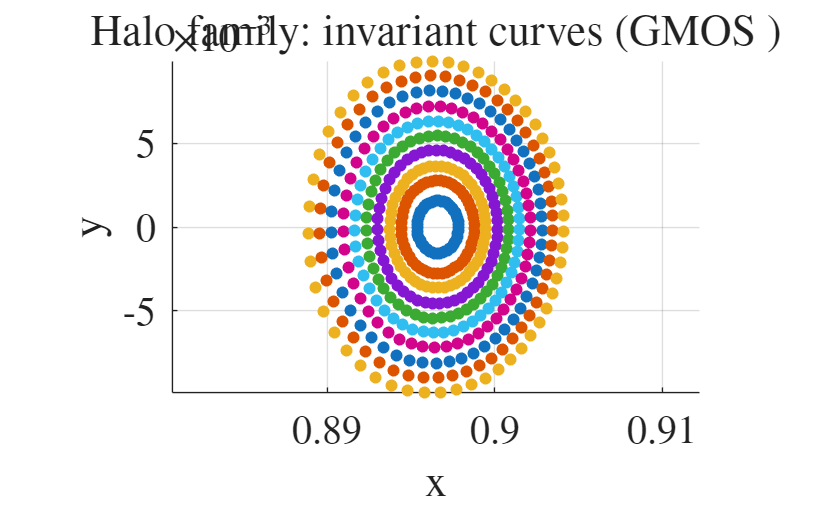


% Plot one torus from the last family member
z = fam.z{100};

%z = fam.z{10};

jList = 1:1:N;
nPeriods = 2;
nSavePerPeriod = 400;

traj = gmos_propagate_qpos_orbits( ...
    z, N, ...
    mu_EM_JPL, jList, nPeriods, nSavePerPeriod, ode_opts);

hold on

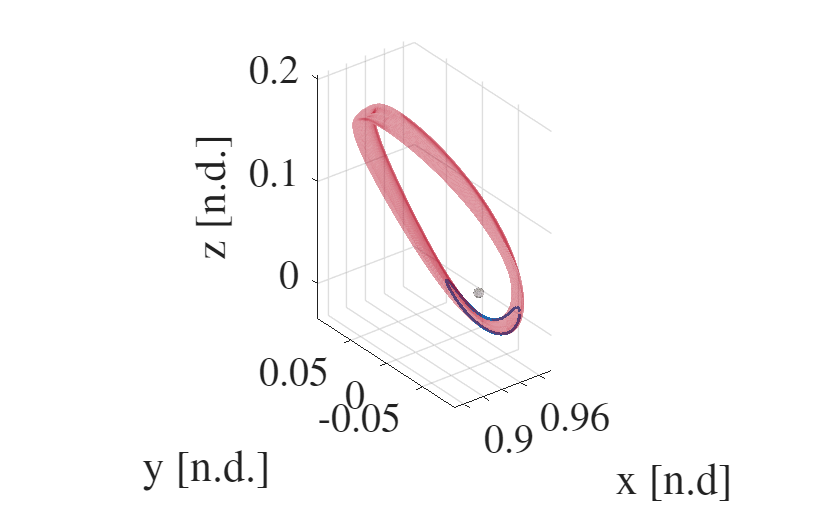


gmos_plot_qpos_orbits_3d( ...
    traj, struct('mode','rgb','rgb',[0.7 0.0 0.1],'alpha',0.08,'lineWidth',1.2),1);

plot_Moon_nd(1e3,60,1);

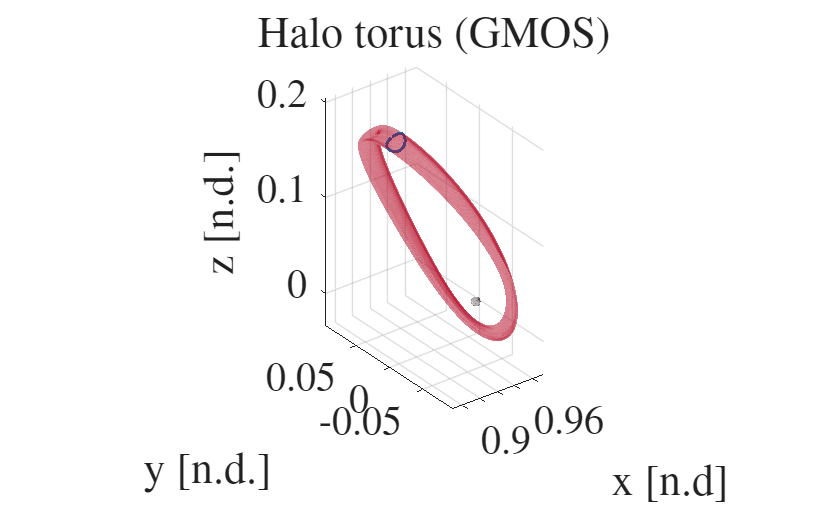




gmos_plot_qpos_orbits_3d( ...
    traj, struct('mode','rgb','rgb',[0.7 0.0 0.1],'alpha',0.1,'lineWidth',1.2),0);
plot_Moon_nd(1e3,1,1);
%plot_Earth_nd(1e3,1,1);

title('Halo torus (GMOS)')

hold off

z = fam.z{102};
[X0, T0, rho] = gmos_unpack_z(z, N);

x0 = X0(:,1);                     % first node on invariant curve
C  = Jacobi_Constant(x0, mu_EM_JPL);

disp('Representative torus initial condition:')

Representative torus initial condition:


disp(x0)

    0.8981
    0.0096
    0.1986
    0.0148
    0.1874
   -0.0408




fprintf('Stroboscopic time T0 = %.15f\n', T0)

Stroboscopic time T0 = 1.949498846364953


fprintf('Phase shift rho = %.15f\n', rho)

Phase shift rho = 0.650562919983875


fprintf('Jacobi constant C = %.15f\n', C)

Jacobi constant C = 3.001531050874794


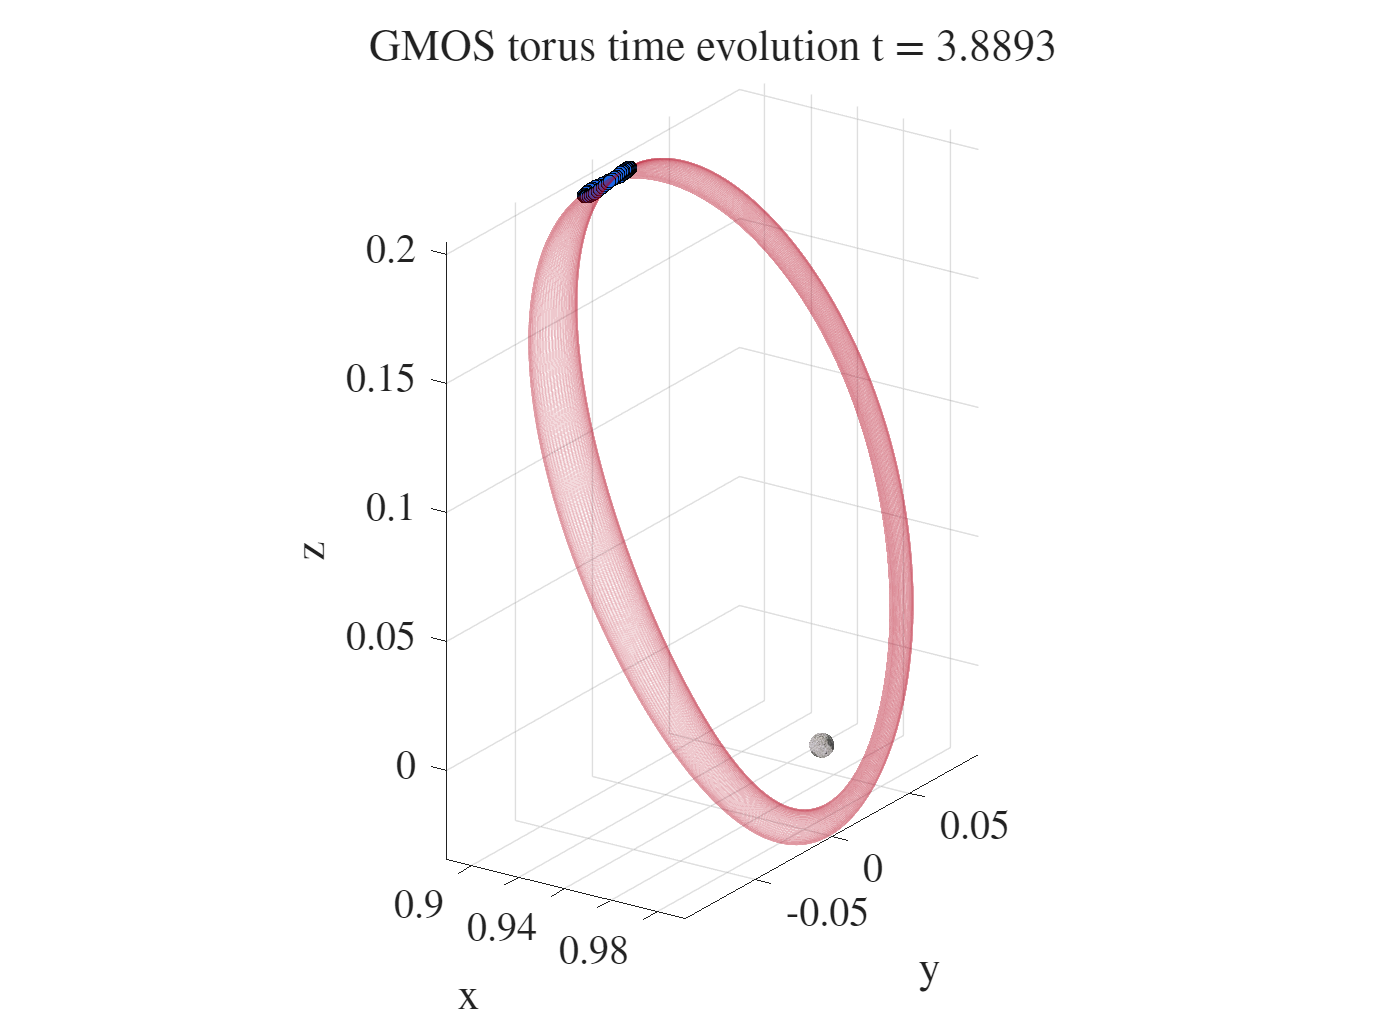

% ------------------------------------------------------------
% Animate one torus with moving particles and rotating camera
% ------------------------------------------------------------
% 
% Y = traj.Y;                      % 6 x K x M
% [~, K, M] = size(Y);
% 
% if isfield(traj, 't')
%     tvec = traj.t;
% elseif isfield(traj, 'tout')
%     tvec = traj.tout;
% else
%     tvec = 1:K;
% end
% 
% % Animation settings
% frameStride = 3;                 % use 1 for smoother, 2-4 for lighter files
% fps = 20;
% outFile = 'gmos_torus_animation.mp4';
% 
% az0 = 35;                        % initial azimuth
% el0 = 22;                        % fixed elevation
% markerSize = 40;
% 
% fig = figure('Color','w','Position',[100 100 1200 900]);
% ax = axes(fig);
% hold(ax,'on');
% grid(ax,'on');
% axis(ax,'equal');
% view(ax, az0, el0);
% xlabel(ax,'x');
% ylabel(ax,'y');
% zlabel(ax,'z');
% title(ax,'GMOS torus time evolution');
% 
% % Faint background torus trajectories
% for m = 1:M
%     r = squeeze(Y(1:3,:,m));
%     patch(ax, ...
%         'XData', [r(1,:) nan], ...
%         'YData', [r(2,:) nan], ...
%         'ZData', [r(3,:) nan], ...
%         'FaceColor', 'none', ...
%         'EdgeColor', [0.7 0.0 0.1], ...
%         'EdgeAlpha', 0.08, ...
%         'LineWidth', 1.0);
% end
% 
% % Moon
% plot_Moon_nd(1e3,60,1);
% 
% % Initial simultaneous ring
% x = squeeze(Y(1,1,:));
% y = squeeze(Y(2,1,:));
% z = squeeze(Y(3,1,:));
% 
% hRing = plot3(ax, [x; x(1)], [y; y(1)], [z; z(1)], ...
%     '-', 'Color', [0.85 0.1 0.1], 'LineWidth', 1.5);
% 
% hPts = scatter3(ax, x, y, z, markerSize, ...
%     'filled', ...
%     'MarkerFaceColor', [0.1 0.4 0.9], ...
%     'MarkerEdgeColor', 'k');
% 
% % Video writer
% v = VideoWriter(outFile, 'MPEG-4');
% v.FrameRate = fps;
% open(v);
% 
% frameIdx = 1:frameStride:K;
% nFrames = numel(frameIdx);
% 
% for ii = 1:nFrames
%     k = frameIdx(ii);
% 
%     x = squeeze(Y(1,k,:));
%     y = squeeze(Y(2,k,:));
%     z = squeeze(Y(3,k,:));
% 
%     set(hPts, 'XData', x, 'YData', y, 'ZData', z);
%     set(hRing, 'XData', [x; x(1)], 'YData', [y; y(1)], 'ZData', [z; z(1)]);
% 
%     % Constant camera rotation
%     az = az0 + 360*(ii-1)/nFrames;
%     view(ax, az, el0);
% 
%     if numel(tvec) == K
%         title(ax, sprintf('GMOS torus time evolution   t = %.4f', tvec(k)));
%     else
%         title(ax, sprintf('GMOS torus time evolution   frame = %d', k));
%     end
% 
%     drawnow;
%     writeVideo(v, getframe(fig));
% end

% 
% close(v);
% fprintf('Saved animation to %s\n', outFile);

Saved animation to gmos_torus_animation.mp4


GMOS using constant Jacobi Constant

% ============================================================
% GMOS FAMILY CONTINUATION WITH FIXED JACOBI CONSTANT, FREE T
% ============================================================

clear
clc

set(0,'DefaultFigureWindowStyle','normal');

set(groot,'DefaultTextInterpreter','latex');
set(groot,'DefaultAxesTickLabelInterpreter','latex');
set(groot,'DefaultLegendInterpreter','latex');
set(groot,'DefaultAxesFontSize',20);
set(groot,'DefaultTextFontSize',22);

% -------------------------
% Constants / seed orbit
% -------------------------
mu_EM_JPL = 1.215058560962404e-2;
mu = mu_EM_JPL;

% ------------------------------------------------------------
% OPTION A: load from your .mat file
% ------------------------------------------------------------
% load('AndresVals.mat');
% mu  = andres.mu;
% xPO0 = andres.X0(:);
% TPO  = andres.T;
% Ctarget = andres.JC;

% ------------------------------------------------------------
% OPTION B: use a JPL orbit directly
% ------------------------------------------------------------
orbit_index = 400;

po = pick_po_from_JPL('DRO_orbits_JPL_IC_Earth_Moon.csv', orbit_index);
xPO0 = po.x0(:);
TPO  = po.T;

% ------------------------------------------------------------
% Choose target Jacobi constant
% ------------------------------------------------------------
% If you already have JC_Lyap in workspace, use that:
% Ctarget = JC_Lyap;

% Otherwise use the periodic orbit Jacobi constant:
Ctarget = Jacobi_Constant(xPO0.', mu);

fprintf('Target Jacobi constant = %.16f\n', Ctarget);

Target Jacobi constant = 2.7402838893160784


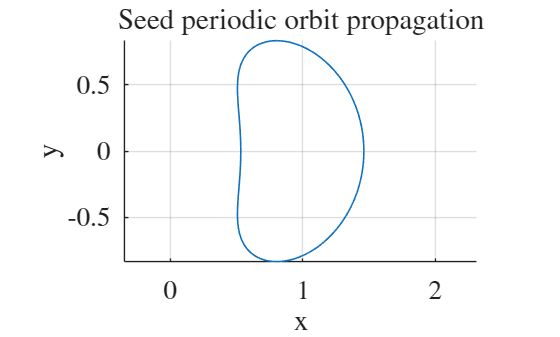


% -------------------------
% Quick trajectory plot of seed PO
% -------------------------
[t_eval, Y_eval] = IntegrateCR3BP_ODE89(xPO0, [0, TPO], mu, 1e3);

figure;
hold on; grid on; axis equal;
plot3(Y_eval(:,1), Y_eval(:,2), Y_eval(:,3), 'LineWidth', 1.2);
xlabel('x');
ylabel('y');
zlabel('z');
title('Seed periodic orbit propagation');


% -------------------------
% ODE options and closure check
% -------------------------
ode_opts = odeset('RelTol',1e-12,'AbsTol',1e-12);

sol = ode89(@(t,y) CR3BP_mu(t,y,mu), [0, TPO], xPO0, ode_opts);
fprintf('PO closure error = %.3e\n', norm(sol.y(:,end) - xPO0));

PO closure error = 4.083e-13



% -------------------------
% GMOS setup
% -------------------------
N = 51;

% IMPORTANT:
% use 'vertical' if you want the vertical family
% use 'planar'   if you want the planar family
mode = 'vertical';

% Two amplitudes so PALC has two corrected starting members
K0 = 1e-6;
K1 = 5e-6;

demo0 = gmos_demo_invariance_only(mu, xPO0, TPO, N, K0, false, mode);

Mode: vertical
Eigenvector projections: planar 2.837e-14, vertical 1.000e+00
Init amplitude [x y z xd yd zd] = [0.00e+00 5.12e-20 8.13e-07 2.01e-20 0.00e+00 1.83e-06]
Max init amplitude: component 6, amp = 1.826e-06
Linearization test at j=1:
  ||dx0||      = 9.137e-07
  ||dx1||      = 8.893e-07
  ||dx1_lin||  = 8.893e-07
  ||dx1-dx1lin|| = 1.648e-11
Inf residual: +rho 1.591e-11, -rho 4.682e-07, using sign 1
||Finv||2   = 1.314e-10
||Finv||inf = 1.591e-11


demo1 = gmos_demo_invariance_only(mu, xPO0, TPO, N, K1, false, mode);

Mode: vertical
Eigenvector projections: planar 2.837e-14, vertical 1.000e+00
Init amplitude [x y z xd yd zd] = [0.00e+00 2.56e-19 4.06e-06 1.00e-19 0.00e+00 9.13e-06]
Max init amplitude: component 6, amp = 9.128e-06
Linearization test at j=1:
  ||dx0||      = 4.568e-06
  ||dx1||      = 4.446e-06
  ||dx1_lin||  = 4.446e-06
  ||dx1-dx1lin|| = 4.147e-10
Inf residual: +rho 3.971e-10, -rho 2.341e-06, using sign 1
||Finv||2   = 3.304e-09
||Finv||inf = 3.971e-10



init0 = demo0.init;
init1 = demo1.init;

% -------------------------
% First reference for phase conditions
% -------------------------
Xref   = init0.X0;
Tref   = init0.T0;
rhoref = init0.rho0;

% Initial unknown vectors z = [X0(:); T; rho]
z0 = gmos_pack_z(init0.X0, init0.T0, init0.rho0);
z1 = gmos_pack_z(init1.X0, init1.T0, init1.rho0);

optsN = struct();
optsN.maxIter = 16;
optsN.tolInf  = 1e-10;
optsN.verbose = true;

% -------------------------
% Correct first seed with fixed C
% -------------------------
[z0_sol, info0] = gmos_newton_fixC_analytic( ...
    z0, N, mu, Xref, Tref, rhoref, Ctarget, ode_opts, optsN);

Newton iter  1: ||F||inf = 1.549e-11, ||F||2 = 1.275e-10



fprintf('seed 0 final ||F||inf = %.3e\n', info0.normInf(end));

seed 0 final ||F||inf = 1.549e-11



[Xref1, Tref1, rhoref1] = gmos_unpack_z(z0_sol, N);

% -------------------------
% Correct second seed with fixed C
% -------------------------
[z1_sol, info1] = gmos_newton_fixC_analytic( ...
    z1, N, mu, Xref1, Tref1, rhoref1, Ctarget, ode_opts, optsN);

Newton iter  1: ||F||inf = 3.967e-10, ||F||2 = 3.300e-09
Newton iter  2: ||F||inf = 9.259e-14, ||F||2 = 2.861e-13



fprintf('seed 1 final ||F||inf = %.3e\n', info1.normInf(end));

seed 1 final ||F||inf = 9.259e-14



% -------------------------
% Check corrected seeds
% -------------------------
[X0a, Ta, rhoa] = gmos_unpack_z(z0_sol, N);
[X0b, Tb, rhob] = gmos_unpack_z(z1_sol, N);

Ca = mean(Jacobi_Constant(X0a.', mu));
Cb = mean(Jacobi_Constant(X0b.', mu));

fprintf('seed 0: T = %.16f, rho = %.16f, mean(C) error = %.3e\n', ...
    Ta, rhoa, abs(Ca - Ctarget));

seed 0: T = 5.8867509764757813, rho = 0.2591380693868175, mean(C) error = 9.313e-13


fprintf('seed 1: T = %.16f, rho = %.16f, mean(C) error = %.3e\n', ...
    Tb, rhob, abs(Cb - Ctarget));

seed 1: T = 5.8867509764570736, rho = 0.2591380694075628, mean(C) error = 0.000e+00



% -------------------------
% Continue family with PALC
% -------------------------
ds     = 1e-2;
nSteps = 250;

if isfile('fam_fixC.mat')
    load('fam_fixC.mat','fam');
else
    fam = gmos_continue_fixC_family( ...
        z0_sol, z1_sol, nSteps, ds, N, mu, Ctarget, ode_opts, optsN);
    save('fam_fixC.mat','fam')
end

beep

fprintf('Computed %d family members.\n', numel(fam.z));

Computed 196 family members.


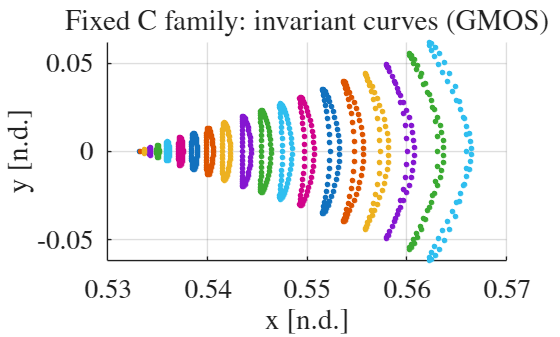


% -------------------------
% Plot representative invariant curves
% -------------------------
idxList = unique(round(linspace(1, numel(fam.z), min(20, numel(fam.z)))));

figure;
hold on;
grid on;
for ii = idxList(:).'
    [X0i, ~, ~] = gmos_unpack_z(fam.z{ii}, N);
    scatter3(X0i(1,:), X0i(2,:), X0i(3,:), 18, 'filled');
end
xlabel('x [n.d.]');
ylabel('y [n.d.]');
zlabel('z [n.d.]');
title('Fixed C family: invariant curves (GMOS)');

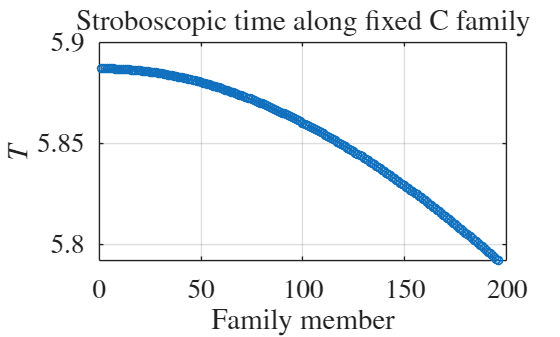


% -------------------------
% Plot T and rho along the family
% -------------------------
nFam = numel(fam.z);
Tfam   = nan(nFam,1);
rhofam = nan(nFam,1);
Cfam   = nan(nFam,1);

for k = 1:nFam
    [Xk, Tk, rhok] = gmos_unpack_z(fam.z{k}, N);
    Tfam(k)   = Tk;
    rhofam(k) = rhok;
    Cfam(k)   = mean(Jacobi_Constant(Xk.', mu));
end

figure;
plot(1:nFam, Tfam, 'o-', 'LineWidth', 1.2);
grid on;
xlabel('Family member');
ylabel('$T$');
title('Stroboscopic time along fixed C family');

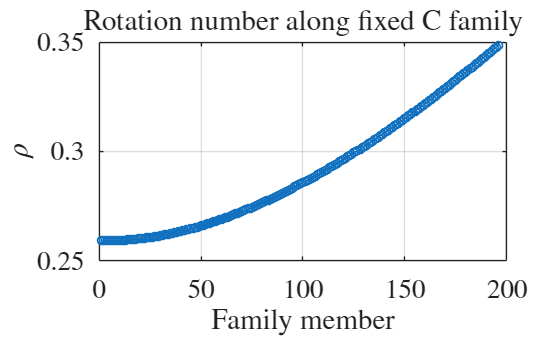


figure;
plot(1:nFam, rhofam, 'o-', 'LineWidth', 1.2);
grid on;
xlabel('Family member');
ylabel('$\rho$');
title('Rotation number along fixed C family');

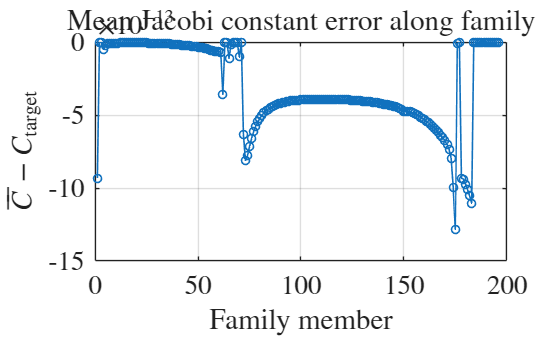


figure;
plot(1:nFam, Cfam - Ctarget, 'o-', 'LineWidth', 1.2);
grid on;
xlabel('Family member');
ylabel('$\overline{C} - C_{\mathrm{target}}$');
title('Mean Jacobi constant error along family');

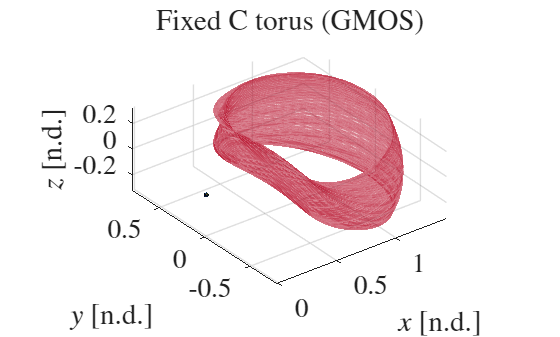


% -------------------------
% Propagate the last family member
% -------------------------
z = fam.z{end};

jList = 1:5:N;
nPeriods = 60;
nSavePerPeriod = 600;

traj = gmos_propagate_qpos_orbits( ...
    z, N, mu, jList, nPeriods, nSavePerPeriod, ode_opts);

figure;
gmos_plot_qpos_orbits_3d( ...
    traj, struct('mode','rgb','rgb',[0.7 0.0 0.1], ...
    'alpha',0.1,'lineWidth',1.2));
hold on;
plot_Moon_nd(1e3,1,1);
plot_Earth_nd(1e3,1,1);
title('Fixed C torus (GMOS)');


% -------------------------
% Accuracy metric along family
% -------------------------
[EGMOS_end, delta_end] = gmos_accuracy_test_paper(z, N, mu, ode_opts);
fprintf('Last family member: EGMOS = %.3e, max(delta) = %.3e\n', ...
    EGMOS_end, max(delta_end));

Last family member: EGMOS = 6.475e-08, max(delta) = 1.299e-07


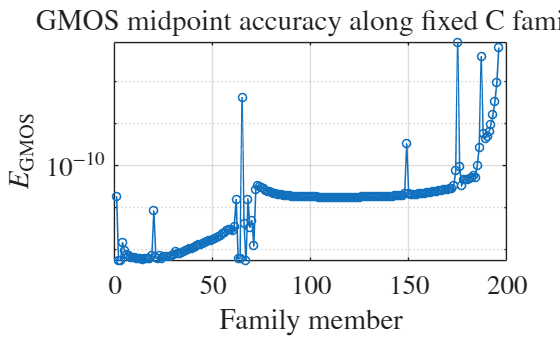


EG = nan(nFam,1);
for k = 1:nFam
    [EG(k), ~] = gmos_accuracy_test_paper(fam.z{k}, N, mu, ode_opts);
end

figure;
semilogy(1:nFam, EG, 'o-', 'LineWidth', 1.2);
grid on;
xlabel('Family member');
ylabel('$E_{\mathrm{GMOS}}$');
title('GMOS midpoint accuracy along fixed C family');

Mu continuation

mu0=mu_EM_JPL

mu0 = 0.0122

mu1=1.0020*mu_EM_JPL

mu1 = 0.0122

z_start=fam.z{end}

z_start =     0.5660
   -0.0000
    0.0000
    0.0000
    0.9855
   -0.2892
    0.5657
   -0.0194
    0.0198
    0.0200
    0.9852
   -0.2859
    0.5648
   -0.0368
    0.0388


Ttarget=fam.T(end)

Ttarget = 5.7918



mu1=1.020*mu_EM_JPL

mu1 = 0.0124

%muVals =  linspace(mu0, mu1, 60);
muVals =  linspace(mu0, mu1, 65);
step_size=muVals(end)-muVals(end-1)

step_size = 3.7971e-06


branch = gmos_continue_fixT_mu_simple( ...
    z_start, muVals, N, Ttarget, ode_opts, optsN);

Newton iter  1: ||F||inf = 7.578e-05, ||F||2 = 4.731e-04
Newton iter  2: ||F||inf = 1.168e-05, ||F||2 = 6.316e-05
Newton iter  3: ||F||inf = 8.730e-09, ||F||2 = 2.748e-08
Newton iter  4: ||F||inf = 2.242e-07, ||F||2 = 8.696e-07
Newton iter  5: ||F||inf = 1.012e-10, ||F||2 = 3.400e-10
Newton iter  6: ||F||inf = 8.094e-14, ||F||2 = 2.622e-13
mu-step 1/64: mu = 0.01215438266762705, T = 5.791790381004302, rho = 0.348578958128141, EGMOS = 9.736e-08, final ||F||inf = 8.094e-14
Newton iter  1: ||F||inf = 7.595e-05, ||F||2 = 4.738e-04
Newton iter  2: ||F||inf = 1.161e-05, ||F||2 = 6.331e-05
Newton iter  3: ||F||inf = 5.732e-09, ||F||2 = 1.898e-08
Newton iter  4: ||F||inf = 6.903e-08, ||F||2 = 2.448e-07
Newton iter  5: ||F||inf = 3.743e-11, ||F||2 = 1.377e-10
mu-step 2/64: mu = 0.01215817972563006, T = 5.791790381004302, rho = 0.348658663501077, EGMOS = 1.557e-07, final ||F||inf = 3.743e-11
Newton iter  1: ||F||inf = 7.611e-05, ||F||2 = 4.746e-04
Newton iter  2: ||F||inf = 1.163e-05, ||F||2 = 6

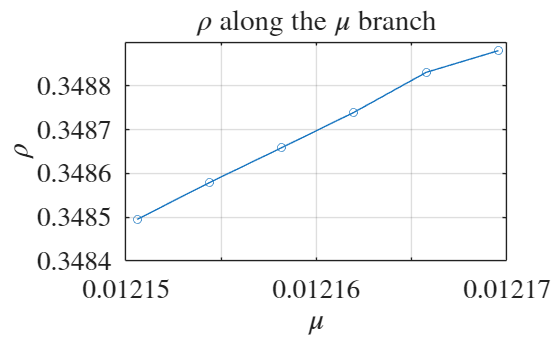

figure;
plot(branch.mu, branch.rho, 'o-'); grid on;
xlabel('$\mu$'); ylabel('$\rho$');
title('$\rho$ along the $\mu$ branch');

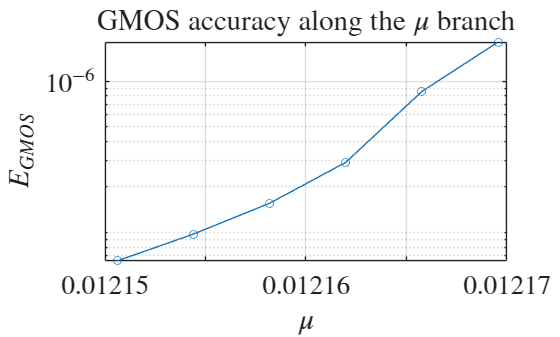


figure;
semilogy(branch.mu, branch.EGMOS, 'o-'); grid on;
xlabel('$\mu$'); ylabel('$E_{GMOS}$');
title('GMOS accuracy along the $\mu$ branch');

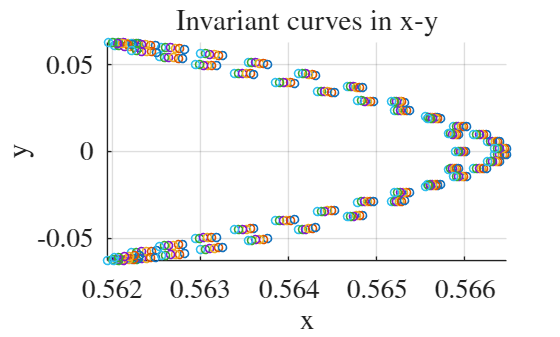

idxList = unique(round(linspace(1, numel(branch.z), min(8, numel(branch.z)))));

figure; hold on; grid on;
for ii = idxList(:).'
    [X0i, ~, ~] = gmos_unpack_z(branch.z{ii}, N);
    plot3(X0i(1,:), X0i(2,:),X0i(3,:), 'o', 'LineWidth', 1.2);
end
xlabel('x'); ylabel('y');
title('Invariant curves in x-y');

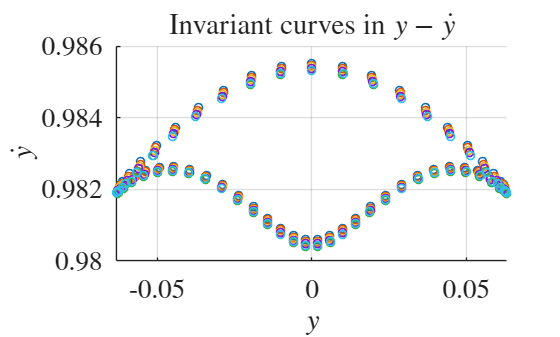


figure; hold on; grid on;
for ii = idxList(:).'
    [X0i, ~, ~] = gmos_unpack_z(branch.z{ii}, N);
    plot(X0i(2,:), X0i(5,:), 'o','LineWidth', 1.2);
end
xlabel('$y$'); ylabel('$\dot{y}$');
title('Invariant curves in $y-\dot{y}$');

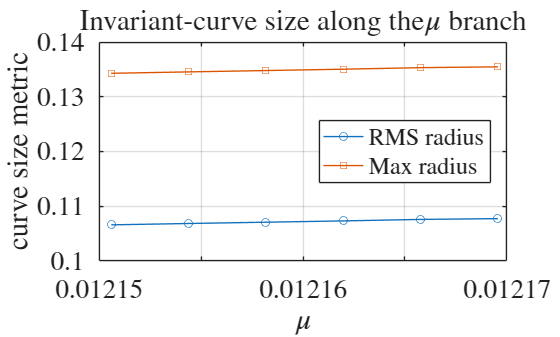

nB = numel(branch.z);
rRMS = nan(nB,1);
rMax = nan(nB,1);

for k = 1:nB
    [Xk, ~, ~] = gmos_unpack_z(branch.z{k}, N);
    Pc = Xk(1:3,:) - mean(Xk(1:3,:),2);
    rk = sqrt(sum(Pc.^2,1));
    rRMS(k) = sqrt(mean(rk.^2));
    rMax(k) = max(rk);
end

figure;
plot(branch.mu, rRMS, 'o-', branch.mu, rMax, 's-'); grid on;
xlabel('$\mu$');
ylabel('curve size metric');
legend('RMS radius','Max radius','Location','best');
title('Invariant-curve size along the$ \mu$ branch');

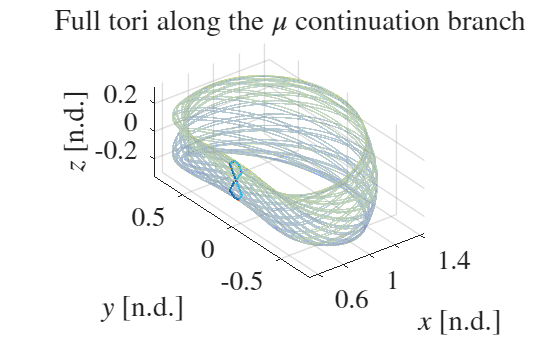

% ------------------------------------------------------------
% Choose which branch members to display
% ------------------------------------------------------------
idxList = unique(round(linspace(1, numel(branch.z), min(8, numel(branch.z)))));
cmap = parula(numel(idxList));

figure;
ax = axes;
hold(ax, 'on');
grid(ax, 'on');
axis(ax, 'equal');
view(ax, 3);

for a = 1:numel(idxList)
    k = idxList(a);

    z_k  = branch.z{k};
    mu_k = branch.mu(k);

    traj_k = gmos_propagate_qpos_orbits( ...
        z_k, N, mu_k, 1:5:N, 4, 200, ode_opts);

    style_k = struct( ...
        'mode', 'rgb', ...
        'rgb', cmap(a,:), ...
        'alpha', 0.10, ...
        'lineWidth', 1.1, ...
        'newFigure', false, ...
        'ax', ax);

    gmos_plot_qpos_orbits_3d(traj_k, style_k, 0);
end

% plot_Moon_nd(1e3,1,1);
% plot_Earth_nd(1e3,1,1);

xlabel('$x$ [n.d.]');
ylabel('$y$ [n.d.]');
zlabel('$z$ [n.d.]');
title('Full tori along the $\mu$ continuation branch');

%Extended PALC with mu

k0 = numel(branch.z) - 1;
k1 = numel(branch.z);

z0_sol = branch.z{1};
z1_sol = branch.z{2};

mu0_sol = branch.mu(k0);
mu1_sol = branch.mu(k1);

y0_sol = [z0_sol(:); mu0_sol];
y1_sol = [z1_sol(:); mu1_sol];


optsPALC = struct();
optsPALC.maxIter = 12;
optsPALC.tolInf = 1e-10;
optsPALC.verbose = true;
optsPALC.computeEGMOS = true;
optsPALC.fdMu = 1e-8;

nSteps = 100;

deltaMu_seed = y1_sol(end) - y0_sol(end);

t_hat0 = (y1_sol - y0_sol) / norm(y1_sol - y0_sol);

deltaMu_target = 1e0 * deltaMu_seed;   % start conservatively
ds = deltaMu_target / t_hat0(end);

branchPALC = gmos_continue_fixT_mu_palc( ...
    y0_sol, y1_sol, nSteps, ds, N, Ttarget, ode_opts, optsPALC);

Newton iter  1: ||F||inf = 3.235e-04, ||F||2 = 1.989e-03, mu = 0.01217336795764208
Newton iter  2: ||F||inf = 2.767e-06, ||F||2 = 1.543e-05, mu = 0.0121153385631679
Newton iter  3: ||F||inf = 4.975e-09, ||F||2 = 3.173e-08, mu = 0.01211655942164544
Newton iter  4: ||F||inf = 4.996e-11, ||F||2 = 2.360e-10, mu = 0.01211653855708127
PALC step 1/100: mu = 0.01211653855708127, T = 5.791790381004302, rho = 0.348664045396249, EGMOS = 1.717e-07, final ||F||inf = 4.996e-11
Newton iter  1: ||F||inf = 1.039e-04, ||F||2 = 6.574e-04, mu = 0.0120977652675646
Newton iter  2: ||F||inf = 2.525e-04, ||F||2 = 1.388e-03, mu = 0.01206265879367353
Newton iter  3: ||F||inf = 1.216e-06, ||F||2 = 6.129e-06, mu = 0.01206531570487721
Newton iter  4: ||F||inf = 1.128e-07, ||F||2 = 4.388e-07, mu = 0.01206544272679845
Newton iter  5: ||F||inf = 5.844e-09, ||F||2 = 2.056e-08, mu = 0.01206555955234824
Newton iter  6: ||F||inf = 1.038e-11, ||F||2 = 5.033e-11, mu = 0.01206556713306084
PALC step 2/100: mu = 0.01206556713

mu1

mu1 = 0.0124

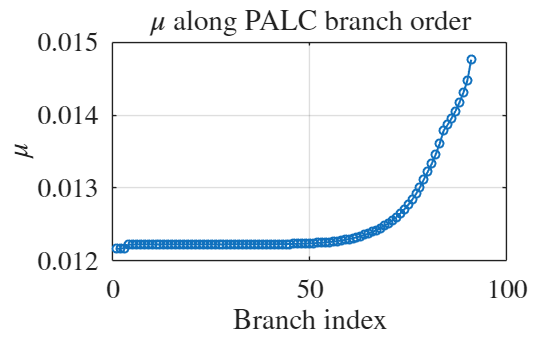

k = 1:numel(branchPALC.mu);

figure;
plot(k, branchPALC.mu, 'o-', 'LineWidth', 1.5);
grid on;
xlabel('Branch index', 'Interpreter', 'latex');
ylabel('$\mu$', 'Interpreter', 'latex');
title('$\mu$ along PALC branch order', 'Interpreter', 'latex');

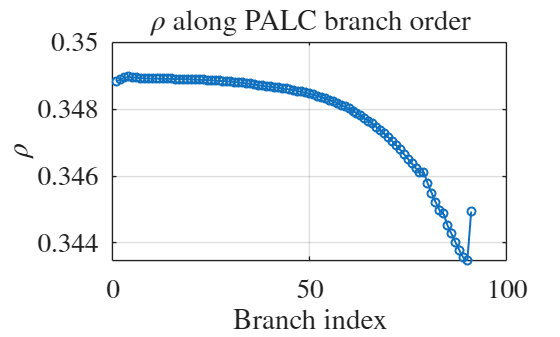


figure;
plot(k, branchPALC.rho, 'o-', 'LineWidth', 1.5);
grid on;
xlabel('Branch index', 'Interpreter', 'latex');
ylabel('$\rho$', 'Interpreter', 'latex');
title('$\rho$ along PALC branch order', 'Interpreter', 'latex');

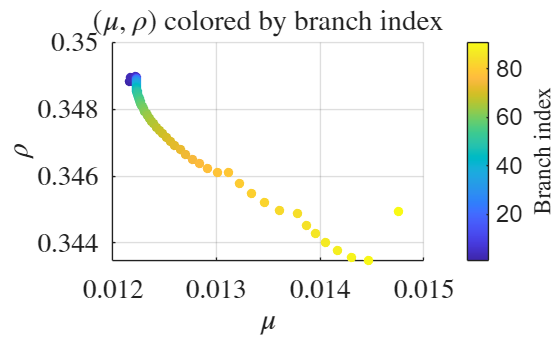

k = 1:numel(branchPALC.mu);

figure;
scatter(branchPALC.mu, branchPALC.rho, 50, k, 'filled');
grid on;
xlabel('$\mu$', 'Interpreter', 'latex');
ylabel('$\rho$', 'Interpreter', 'latex');
title('$(\mu,\rho)$ colored by branch index', 'Interpreter', 'latex');
cb = colorbar;
cb.Label.String = 'Branch index';
cb.Label.Interpreter = 'latex';

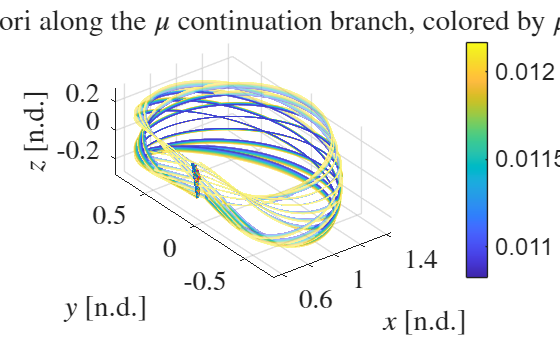

idxList = 1:numel(branchPALC.z);
muVals = branchPALC.mu(idxList);

muMin = min(muVals);
muMax = max(muVals);
cmap = parula(256);

figure;
ax = axes;
hold(ax, 'on');
grid(ax, 'on');
axis(ax, 'equal');
view(ax, 3);

for a = 1:numel(idxList)
    k = idxList(a);

    z_k  = branchPALC.z{k};
    mu_k = branchPALC.mu(k);

    cIdx = 1 + round((size(cmap,1)-1) * (mu_k - muMin) / max(muMax - muMin, eps));
    cIdx = max(1, min(size(cmap,1), cIdx));
    thisColor = cmap(cIdx,:);

    traj_k = gmos_propagate_qpos_orbits( ...
        z_k, N, mu_k, 1:20:N, 4, 100, ode_opts);

    style_k = struct( ...
        'mode', 'rgb', ...
        'rgb', thisColor, ...
        'alpha', 0.10, ...
        'lineWidth', 1.1, ...
        'newFigure', false, ...
        'ax', ax);

    gmos_plot_qpos_orbits_3d(traj_k, style_k, 0);
end

xlabel('$x$ [n.d.]');
ylabel('$y$ [n.d.]');
zlabel('$z$ [n.d.]');
title('Full tori along the $\mu$ continuation branch, colored by $\mu$');

colormap(ax, cmap);
caxis(ax, [muMin muMax]);
cb = colorbar(ax);
cb.Label.String = '$\mu$';
cb.Label.Interpreter = 'latex';

%%Modified weighted PALC with fixed mu direction

% Assume branchSimple came from gmos_continue_fixT_mu_simple
% and contains two consecutive good seed points on the desired branch.

% Extended weighted PALC with mu

k0 = numel(branch.z) - 1;
k1 = numel(branch.z);

z0_sol  = branch.z{k0};
z1_sol  = branch.z{k1};

mu0_sol = branch.mu(k0);
mu1_sol = branch.mu(k1);

y0_sol = [z0_sol(:); mu0_sol];
y1_sol = [z1_sol(:); mu1_sol];

optsPALC = struct();
optsPALC.maxIter = 12;
optsPALC.tolInf = 1e-10;
optsPALC.verbose = true;
optsPALC.verboseStep = true;
optsPALC.computeEGMOS = true;
optsPALC.fdMu = 1e-8;

optsPALC.maxBacktrack = 12;
optsPALC.backtrackFactor = 0.5;
optsPALC.growFactor = 1.12;
optsPALC.enforceMuDirection = true;

nSteps = 250;

scale = gmos_build_palc_scaling_mu(y0_sol, y1_sol, N, struct());

deltaMu_seed = y1_sol(end) - y0_sol(end);

dy_seed_scaled = scale.w .* (y1_sol - y0_sol);
t_hat0 = dy_seed_scaled / norm(dy_seed_scaled);

deltaMu_target = 1e0 * deltaMu_seed;
ds = (scale.w(end) * deltaMu_target) / t_hat0(end);

tic
branchPALC = gmos_continue_fixT_mu_palc_weighted( ...
    y0_sol, y1_sol, nSteps, ds, N, Ttarget, ode_opts, optsPALC);

Newton iter  1: ||F||inf = 1.336e-05, ||F||2 = 6.025e-05, mu = 0.01217336795764208
Newton iter  2: ||F||inf = 3.591e-08, ||F||2 = 1.030e-07, mu = 0.01217278000158723
Newton iter  3: ||F||inf = 6.992e-08, ||F||2 = 3.274e-07, mu = 0.01217292567206278
Newton iter  4: ||F||inf = 1.959e-09, ||F||2 = 7.595e-09, mu = 0.01217278764485883
Newton iter  5: ||F||inf = 1.026e-12, ||F||2 = 5.096e-12, mu = 0.01217278762636272
PALC step 1/250: mu = 0.01217278762636272, T = 5.791790381004302, rho = 0.348930426999679, EGMOS = 4.244e-06, ds = 1.755e+01, final ||F||inf = 1.026e-12
Newton iter  1: ||F||inf = 1.682e-05, ||F||2 = 7.288e-05, mu = 0.01217631266367115
Newton iter  2: ||F||inf = 7.873e-06, ||F||2 = 5.064e-05, mu = 0.01221550465205334
Newton iter  3: ||F||inf = 8.780e-07, ||F||2 = 2.160e-06, mu = 0.01222075472854447
Newton iter  4: ||F||inf = 4.088e-08, ||F||2 = 1.518e-07, mu = 0.01222182586822366
Newton iter  5: ||F||inf = 1.740e-09, ||F||2 = 6.096e-09, mu = 0.0122218859531057
Newton iter  6: ||

toc


branchPALC_stopped=branchPALC;

branchPALC_stopped = struct with fields:
          y: {91×1 cell}
          z: {91×1 cell}
         mu: [91×1 double]
          T: [91×1 double]
        rho: [91×1 double]
       info: {91×1 cell}
    success: [91×1 logical]
     dsUsed: [91×1 double]
      scale: [1×1 struct]
      EGMOS: [91×1 double]


% --------------------------------------------
% Restart weighted mu-PALC from last converged point
% --------------------------------------------

% If success flags are meaningful, use them
if isfield(branchPALC_stopped, 'success') && ~isempty(branchPALC_stopped.success)
    goodIdx = find(branchPALC_stopped.success);
else
    goodIdx = 1:numel(branchPALC_stopped.z);
end

if numel(goodIdx) < 2
    error('Need at least two converged branch members to restart PALC.');
end

k0 = goodIdx(end-3);
k1 = goodIdx(end-2);

fprintf('Restarting from converged members k0 = %d and k1 = %d\n', k0, k1);

Restarting from converged members k0 = 88 and k1 = 89


fprintf('mu0 = %.16f\n', branchPALC_stopped.mu(k0));

mu0 = 0.0141690139469123


fprintf('mu1 = %.16f\n', branchPALC_stopped.mu(k1));

mu1 = 0.0143025630153877



z0_sol  = branchPALC_stopped.z{k0};
z1_sol  = branchPALC_stopped.z{k1};

mu0_sol = branchPALC_stopped.mu(k0);
mu1_sol = branchPALC_stopped.mu(k1);

y0_sol = [z0_sol(:); mu0_sol];
y1_sol = [z1_sol(:); mu1_sol];

% Rebuild weighted tangent and choose a more conservative restart step
scale = gmos_build_palc_scaling_mu(y0_sol, y1_sol, N, struct());

dy_seed_scaled = scale.w .* (y1_sol - y0_sol);
t_hat0 = dy_seed_scaled / norm(dy_seed_scaled);

deltaMu_seed = y1_sol(end) - y0_sol(end);

% Restart more conservatively than before
deltaMu_target = 0.25 * deltaMu_seed;
ds = (scale.w(end) * deltaMu_target) / t_hat0(end);

fprintf('Restart ds = %.6e\n', ds);

Restart ds = 4.387482e+00


fprintf('Restart deltaMu_target = %.6e\n', deltaMu_target);

Restart deltaMu_target = 3.338727e-05



% Make restart options a bit safer
optsPALC_restart = optsPALC;
optsPALC_restart.maxBacktrack = 14;
optsPALC_restart.backtrackFactor = 0.5;
optsPALC_restart.growFactor = 1.05;
optsPALC_restart.enforceMuDirection = true;

nSteps_restart = 100;

tic
branchPALC_more = gmos_continue_fixT_mu_palc_weighted( ...
    y0_sol, y1_sol, nSteps_restart, ds, N, Ttarget, ode_opts, optsPALC_restart);

Newton iter  1: ||F||inf = 2.173e-05, ||F||2 = 1.385e-04, mu = 0.01433595028250659
Newton iter  2: ||F||inf = 5.472e-07, ||F||2 = 3.480e-06, mu = 0.01433814899357369
Newton iter  3: ||F||inf = 3.690e-11, ||F||2 = 2.216e-10, mu = 0.01433816601482038
PALC step 1/100: mu = 0.01433816601482038, T = 5.791790381004302, rho = 0.343524469527114, EGMOS = 3.138e-11, ds = 4.387e+00, final ||F||inf = 3.690e-11
Newton iter  1: ||F||inf = 1.073e-05, ||F||2 = 8.812e-05, mu = 0.01437533981034326
Newton iter  2: ||F||inf = 1.360e-06, ||F||2 = 8.763e-06, mu = 0.01437800567428518
Newton iter  3: ||F||inf = 4.201e-10, ||F||2 = 2.704e-09, mu = 0.01437805224978922
Newton iter  4: ||F||inf = 2.851e-11, ||F||2 = 1.841e-10, mu = 0.01437806418150731
PALC step 2/100: mu = 0.01437806418150731, T = 5.791790381004302, rho = 0.343515227965267, EGMOS = 2.610e-11, ds = 4.607e+00, final ||F||inf = 2.851e-11
Newton iter  1: ||F||inf = 1.386e-05, ||F||2 = 1.171e-04, mu = 0.01441942841699271
Newton iter  2: ||F||inf = 1.2

toc

Elapsed time is 247.287056 seconds.


% --------------------------------------------
% Stitch old stopped branch with restarted continuation
% --------------------------------------------

 
branchPALC_all = struct();

branchPALC_all.y = [ ...
    branchPALC_stopped.y(1:k1); ...
    branchPALC_more.y(2:end)];

branchPALC_all.z = [ ...
    branchPALC_stopped.z(1:k1); ...
    branchPALC_more.z(2:end)];

branchPALC_all.mu = [ ...
    branchPALC_stopped.mu(1:k1); ...
    branchPALC_more.mu(2:end)];

branchPALC_all.T = [ ...
    branchPALC_stopped.T(1:k1); ...
    branchPALC_more.T(2:end)];

branchPALC_all.rho = [ ...
    branchPALC_stopped.rho(1:k1); ...
    branchPALC_more.rho(2:end)];

branchPALC_all.info = [ ...
    branchPALC_stopped.info(1:k1); ...
    branchPALC_more.info(2:end)];

branchPALC_all.success = [ ...
    branchPALC_stopped.success(1:k1); ...
    branchPALC_more.success(2:end)];

branchPALC_all.dsUsed = [ ...
    branchPALC_stopped.dsUsed(1:k1); ...
    branchPALC_more.dsUsed(2:end)];

branchPALC_all.EGMOS = [ ...
    branchPALC_stopped.EGMOS(1:k1); ...
    branchPALC_more.EGMOS(2:end)];

branchPALC_all.scale = branchPALC_more.scale;

%save('branchPALC_all.mat', 'branchPALC_all', '-v7.3')

load('branchPALC_all.mat', 'branchPALC_all')

%branchMaster = branchPALC_all;


extOpts = struct();
extOpts.tailSkip = 20;          % use 1, 2, or 3 if the tail looks suspicious
extOpts.deltaMuScale = 5.5;   % conservative restart
extOpts.nSteps = 15;
extOpts.saveFile = 'branchMaster_muPALC.mat';
extOpts.verbose = true;

tic
[branchMaster, meta1] = gmos_extend_fixT_mu_branch_weighted( ...
    branchMaster, N, Ttarget, ode_opts, optsPALC, extOpts);


Restarting weighted mu-PALC from k0 = 159, k1 = 160
mu0 = 0.0162439468521131
mu1 = 0.0162476029641454
deltaMu_seed   = 3.656112e-06
deltaMu_target = 2.010862e-05
ds restart     = 9.652461e+01
Newton iter  1: ||F||inf = 4.029e-06, ||F||2 = 2.421e-05, mu = 0.0162677115803227
Newton iter  2: ||F||inf = 2.639e-09, ||F||2 = 1.783e-08, mu = 0.01626758566206054
Newton iter  3: ||F||inf = 3.311e-12, ||F||2 = 4.075e-12, mu = 0.01626758727889168
PALC step 1/15: mu = 0.01626758727889168, T = 5.791790381004302, rho = 0.340641012869883, EGMOS = 7.533e-13, ds = 9.652e+01, final ||F||inf = 3.311e-12
Newton iter  1: ||F||inf = 8.421e-06, ||F||2 = 5.124e-05, mu = 0.01628956657505173
Newton iter  2: ||F||inf = 1.513e-08, ||F||2 = 1.022e-07, mu = 0.01628923898818123
Newton iter  3: ||F||inf = 1.194e-12, ||F||2 = 2.005e-12, mu = 0.01628923763940321
PALC step 2/15: mu = 0.01628923763940321, T = 5.791790381004302, rho = 0.340699005194859, EGMOS = 6.395e-13, ds = 1.062e+02, final ||F||inf = 1.194e-12
Newton

toc

Elapsed time is 24.342831 seconds.



beep

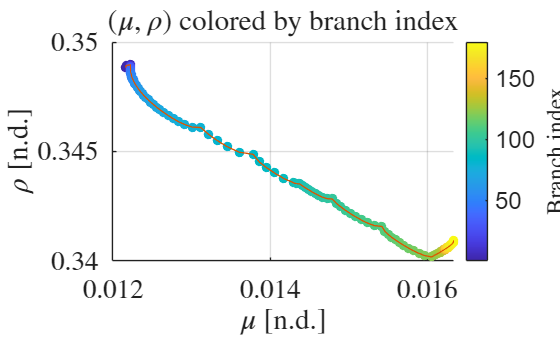



figure;
hold on;
grid on;

idx = 1:numel(branchMaster.mu);
scatter(branchMaster.mu, branchMaster.rho, 50, idx, 'filled');
plot(branchMaster.mu, branchMaster.rho, '-', 'LineWidth', 1.0);

xlabel('$\mu$ [n.d.]');
ylabel('$\rho$ [n.d.]');
title('$(\mu,\rho)$ colored by branch index');

cb = colorbar;
cb.Label.String = 'Branch index';
cb.Label.Interpreter = 'latex';

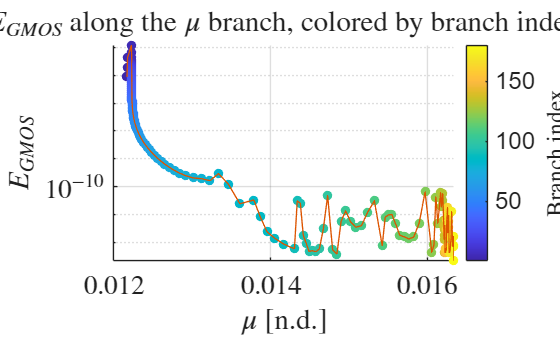



figure;
hold on;
grid on;

idx = 1:numel(branchMaster.mu);

scatter(branchMaster.mu, branchMaster.EGMOS, 50, idx, 'filled');
semilogy(branchMaster.mu, branchMaster.EGMOS, '-', 'LineWidth', 1.0);

set(gca, 'YScale', 'log');

xlabel('$\mu$ [n.d.]');
ylabel('$E_{GMOS}$');
title('$E_{GMOS}$ along the $\mu$ branch, colored by branch index');

cb = colorbar;
cb.Label.String = 'Branch index';
cb.Label.Interpreter = 'latex';

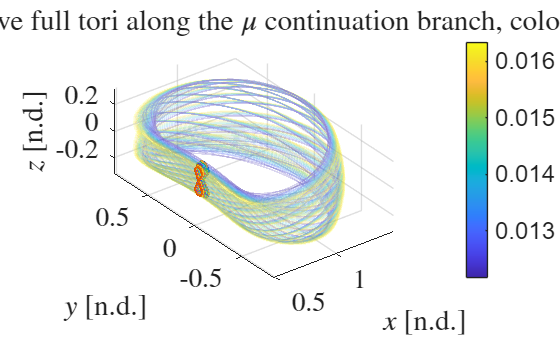

muAll  = branchMaster.mu(:);
rhoAll = branchMaster.rho(:);
nAll   = numel(muAll);

muMin = min(muAll);
muMax = max(muAll);
cmap  = parula(256);

% ------------------------------------------------------------
% Smart representative selection
% ------------------------------------------------------------
nShowBase = 10;   % number of roughly uniform-in-mu samples

muTargets = linspace(muMin, muMax, nShowBase);
idxMu = zeros(nShowBase,1);

for i = 1:nShowBase
    [~, idxMu(i)] = min(abs(muAll - muTargets(i)));
end

% Include endpoints
idxSpecial = [1; nAll];

% Include strongest bend in the (mu,rho) branch if possible
if nAll >= 4
    s1 = diff(rhoAll) ./ diff(muAll);
    bend = abs(diff(s1));
    [~, ib] = max(bend);
    idxSpecial(end+1) = ib + 1;
end

idxList = unique([idxSpecial; idxMu], 'stable');

% ------------------------------------------------------------
% Plot selected full tori
% ------------------------------------------------------------
figure;
ax = axes;
hold(ax, 'on');
grid(ax, 'on');
axis(ax, 'equal');
view(ax, 3);

for a = 1:numel(idxList)
    k = idxList(a);

    z_k  = branchMaster.z{k};
    mu_k = branchMaster.mu(k);

    cIdx = 1 + round((size(cmap,1)-1) * (mu_k - muMin) / max(muMax - muMin, eps));
    cIdx = max(1, min(size(cmap,1), cIdx));
    thisColor = cmap(cIdx,:);

    traj_k = gmos_propagate_qpos_orbits( ...
        z_k, N, mu_k, 1:5:N, 2, 600, ode_opts);

    style_k = struct( ...
        'mode', 'rgb', ...
        'rgb', thisColor, ...
        'alpha', 0.10, ...
        'lineWidth', 1.1, ...
        'newFigure', false, ...
        'ax', ax);

    gmos_plot_qpos_orbits_3d(traj_k, style_k, 0);
end

xlabel('$x$ [n.d.]');
ylabel('$y$ [n.d.]');
zlabel('$z$ [n.d.]');
title('Representative full tori along the $\mu$ continuation branch, colored by $\mu$');

colormap(ax, cmap);
caxis(ax, [muMin muMax]);
cb = colorbar(ax);
cb.Label.String = '$\mu$';
cb.Label.Interpreter = 'latex';

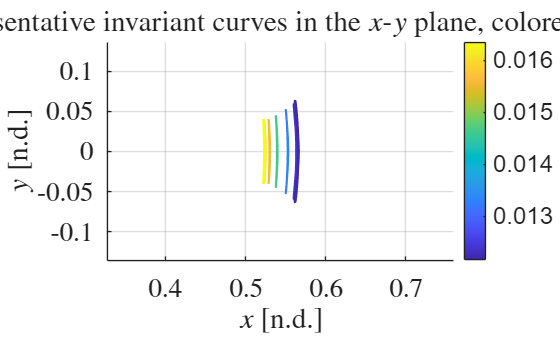

% ============================================================
% Representative invariant curves from branchMaster
% Assumes:
%   [branchMaster, meta1] = gmos_extend_fixT_mu_branch_weighted(...)
% ============================================================

branchUse = branchMaster;

% ------------------------------------------------------------
% Choose representative members
% ------------------------------------------------------------
nShow = 12;
idxList = unique(round(linspace(1, numel(branchUse.z), min(nShow, numel(branchUse.z)))));

muMin = min(branchUse.mu);
muMax = max(branchUse.mu);
cmap  = parula(256);

curveColors = zeros(numel(idxList), 3);
for a = 1:numel(idxList)
    mu_k = branchUse.mu(idxList(a));
    cIdx = 1 + round((size(cmap,1)-1) * (mu_k - muMin) / max(muMax - muMin, eps));
    cIdx = max(1, min(size(cmap,1), cIdx));
    curveColors(a,:) = cmap(cIdx,:);
end

% ------------------------------------------------------------
% x-y invariant curves
% ------------------------------------------------------------
figure;
ax1 = axes;
hold(ax1, 'on');
grid(ax1, 'on');
axis(ax1, 'equal');

for a = 1:numel(idxList)
    k = idxList(a);

    z_k = branchUse.z{k};
    [X0_k, ~, ~] = gmos_unpack_z(z_k, N);

    Xc = [X0_k, X0_k(:,1)];
    plot3(Xc(1,:), Xc(2,:), Xc(3,:),...
        'LineWidth', 1.6, ...
        'Color', curveColors(a,:));
end

xlabel('$x$ [n.d.]');
ylabel('$y$ [n.d.]');
title('Representative invariant curves in the $x$-$y$ plane, colored by $\mu$');

colormap(ax1, cmap);
caxis(ax1, [muMin muMax]);
cb1 = colorbar(ax1);
cb1.Label.String = '$\mu$';
cb1.Label.Interpreter = 'latex';

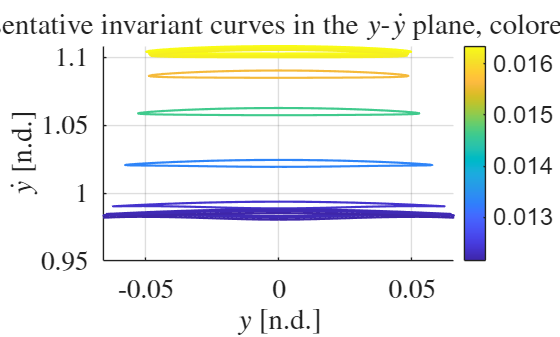


% ------------------------------------------------------------
% y-v_y invariant curves
% ------------------------------------------------------------
figure;
ax2 = axes;
hold(ax2, 'on');
grid(ax2, 'on');

for a = 1:numel(idxList)
    k = idxList(a);

    z_k = branchUse.z{k};
    [X0_k, ~, ~] = gmos_unpack_z(z_k, N);

    Xc = [X0_k, X0_k(:,1)];
    plot(Xc(2,:), Xc(5,:), ...
        'LineWidth', 1.6, ...
        'Color', curveColors(a,:));
end

xlabel('$y$ [n.d.]');
ylabel('$\dot{y}$ [n.d.]');
title('Representative invariant curves in the $y$-$\dot{y}$ plane, colored by $\mu$');

colormap(ax2, cmap);
caxis(ax2, [muMin muMax]);
cb2 = colorbar(ax2);
cb2.Label.String = '$\mu$';
cb2.Label.Interpreter = 'latex';